Author: **Arjan Gupta**

Due: April 3, 2023

Class: RBE 501

Institution: Worcester Polytechnic Institute

clear; close all; clc;

## Preliminary Setup

### Build Denso's HSR robot with Robotics Toolkit

In the prompt of this assignment, we are given the following table.


$$\matrix{
\text{Link}    	& a_i 	& \alpha_i &  d_i & \theta_i  \cr
1			& 205 			& 0	& 220	& \theta_1			\cr
2			& 275 			& 0		& 0	& \theta_2		\cr
3			& 0 			& 0			& d_3 & 0	\cr
4	        & 0 			& 0 		    & 0 & \theta_4					\cr
}$$


To implement this, we first define joint variables.

theta1 = 0;
theta2 = 0;
d3 = 0;
theta4 = 0;

Now, we can import the DH params from the given table.

% Link lengths
L1 = sqrt((205)^2 + (220)^2)/1000;
L2 = 0.275;
% DH parameters
dhparams = [0.205   0   	0.220   theta1;
            0.275	0       0       theta2;
            0   	0	    d3	    0;
            0       0       0       theta4];

Next, we create a rigid body tree object to build the Denso HSR robot. This is necessary to begin assigning rigid bodies (links) of the robot, to represent moving parts.

denso_robot = rigidBodyTree("DataFormat","column");

We can begin building the robot now. We make sure that the order of the joints is revolute, revolute, prismatic, revolute. This is because, as shown in the information web-page of Denso Robotics, the HSR robot is essentially a SCARA robot with a revolute tool-tip.

As described in the tutorial of the Robotics Toolkit, we need to assign bodies and joints, as shown in the following code.

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','prismatic');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');

We can then set their transforms (this is done by using rows of the DH table we are given). 

setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');

Joints also need to be associated with their bodies, as shown in the following code.

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;

Finally, bodies can be assigned to the rigid-body tree.

addBody(denso_robot,body1,'base')
addBody(denso_robot,body2,'body1')
addBody(denso_robot,body3,'body2')
addBody(denso_robot,body4,'body3')

We can verify that our robot was built correctly by showing its details.

showdetails(denso_robot)

--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


### Show target positions

In the video, the robot picks up the 4 sets of water bottles and moves them to new locations (this sequence is the first 8 moves/goal positions). Then it picks them up again, in a different order, and puts them back in the starting positions (another 8 moves). In the following set of goal positions, we have shown the first 8 positions from the video. For our angles, we have chosen estimated values such that the end-effector lies on the 180 degree arc.

goalPos = zeros(4,1,8);

The following is the first position of the robot shown in the video, i.e. when the robot picks up the first set of water bottles.

goalPos(:,:,1) = [deg2rad(0);deg2rad(0);-0.2;0]; % Goal position 1

Similarly, set the positions where the robot drops off the first set of water bottles,

goalPos(:,:,2) = [deg2rad(50);deg2rad(15);-0.2;0]; % Goal position 2

picks up the second set of water bottles,

goalPos(:,:,3) = [deg2rad(7.5);deg2rad(7.5);-0.2;0]; % Goal position 3

drops off the second set of water bottles,

goalPos(:,:,4) = [deg2rad(55);deg2rad(35);-0.2;0]; % Goal position 4

picks up the third set of water bottles,

goalPos(:,:,5) = [deg2rad(180);deg2rad(0);-0.2;0]; % Goal position 5

drops off the third set of water bottles,

goalPos(:,:,6) = [deg2rad(140);deg2rad(-25);-0.2;0]; % Goal position 6

picks up the fourth set of water bottles,

goalPos(:,:,7) = [deg2rad(160);deg2rad(5);-0.2;0]; % Goal position 7

drops off the fourth set of water bottles,

goalPos(:,:,8) = [deg2rad(115);deg2rad(-15);-0.2;0]; % Goal position 8

picks up the third set of water bottles,

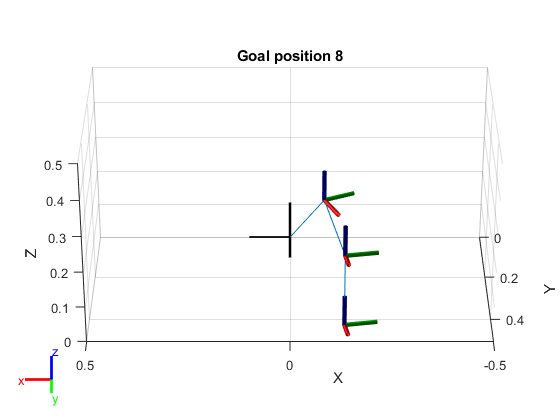

for i = 1:8
    show(denso_robot,goalPos(:,:,i));
    axis([-0.500,0.500,0,0.500,0,0.500]) % Set axes to be like video
    view(180,30) % Adjust camera view
    title(sprintf("Goal position %d",i))
    pause(1)
end

### Set Physical Properties

Set masses and moments of inertia.

% Masses for links (in kgs)
linkMass = zeros(4,1);
linkMass(1) = 3.0;
linkMass(2) = 2.75;
linkMass(3) = 2.0;
linkMass(4) = 1;
% Moments of inertia (in kgm^2)
I1 = 0.1;
I2 = 0.1;
I3 = 0; % prismatic
I4 = 0.01;
% Set the masses
body1.Mass = linkMass(1);
body2.Mass = linkMass(2);
body3.Mass = linkMass(3);
body4.Mass = linkMass(4);
% Set the centers of masses
body1.CenterOfMass = [L1/2, 0, 0];
body2.CenterOfMass = [L2/2, 0, 0];
body3.CenterOfMass = [d3/2, 0, 0]; % variable prismatic length
body4.CenterOfMass = [0,0,0];
% Set the inertias
body1.Inertia = [I1,I1,I1,0,0,0];
body2.Inertia = [I2,I2,I2,0,0,0];
body3.Inertia = [0,0,0,0,0,0];
body4.Inertia = [I4,I4,I4,0,0,0];

## Problem 1

The aim of problem 1 is to visualize the joint torques for each joint as the robot moves along the trajectory in the video.

### Force PD Controller

Our approach is to implement a force proportional-derivative controller to start with an arbitrary acceleration and use inverse dynamics to obtain the joint torques.

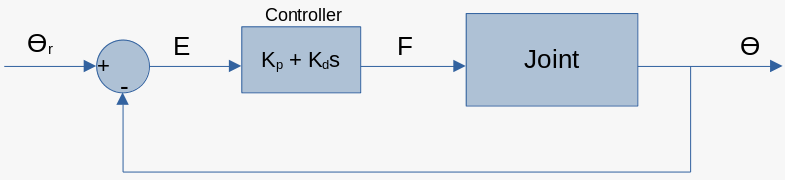

The overall formula for our controller is given as,


$$F=K_p E+K_d \dot{E} =K_p E-K_d v$$


In this formula, the error for our controller, $E$ is calculated as $E=\theta_r -\theta$. This error is then with the proportional multiplier (gain) $K_p$ to obtain the first term of our controller. For the second term, the derivative of the error is calculated as $\dot{E} =\dot{\theta_r } -\dot{\theta} =0-\dot{\theta} =-v$, i.e. the negative of the current velocities of the joints. This derivative of the error is then multiplied with the derivative gain, $K_d$.

For every moment in time, as we move our robot, we can use the controller formula to calculate the new set of forces that we would like to apply to our robot. By dividing the forces by the masses, we obtain the current linear accelerations we would like to apply to the joints. Then, we need to supply these current accelerations, current velocities, and current position to MATLAB's `inverseDynamics` in-built function, in order to output joint torques to apply to our motors.

Now let us set up some variables for our controller.

% Controller proportional gain
Kp = [50;40;100;0];
% Controller derivative gain
Kd = [6;4;11;0];
% Create timing array for controller to run
timeStep = 0.05; % arbitrarily small time step
timeLimit = 500;
timeArr = 0:timeStep:timeLimit;
[~,timeArrLen] = size(timeArr);
% Starting positions, velocities, accelerations
jointPosCurr    = [0;0;0;0];
jointVelsCurr   = [0;0;0;0];
jointAccelsCurr = [0;0;0;0];
% Array for capturing joint torques
jointTorquesArr = zeros(4,1,timeArrLen);

Run our controller, and capture the joint torques.

i = 1;
goalNum = 1;
Kp_var = Kp;
Kd_var = Kd;
for t = timeArr
    % Current goal position
    currGoal = goalPos(:,:,goalNum);
    % Calculate error and error-derivative
    error = goalPos(:,:,goalNum) - jointPosCurr;
    error_prime = -1*jointVelsCurr;
    % Form forces
    F = Kp_var.*error + Kd_var.*error_prime;
    % Form new accelerations
    jointAccelsCurr = F./linkMass;
    % Get joint torques
    jointTorquesArr(:,:,i) = inverseDynamics(denso_robot,jointPosCurr,jointVelsCurr,jointAccelsCurr);
    i = i + 1;
    % Move the robot (update position and velocity)
    jointVelsCurr = jointVelsCurr + jointAccelsCurr*timeStep;
    jointPosCurr  = jointPosCurr + jointVelsCurr*timeStep
    % Check if we've reached goal within tolerance:
    % 0.05 radian and 0.01 m tolerance
    if (ismembertol(jointPosCurr(2,:),currGoal(2,:),0.2))
        Kp_var(1,1) = 0;
        Kp_var(2,1) = 0;
        Kd_var(1,1) = 0;
        Kd_var(2,1) = 0;
    end
    if (ismembertol(jointPosCurr(2,:),currGoal(2,:),0.2) && abs(error(3,1)) <= 0.01)
        fprintf("Reached goal %d\n",goalNum);
        goalNum = goalNum + 1;
        % Retract prismatic joint
        jointPosCurr(3,1) = 0;
        % Reset gains
        Kp_var = Kp;
        Kd_var = Kd;
    end
    % Check if we've reached all goals
    if (goalNum > 8)
        fprintf("Reached all goals, stopping.\n");
        break;
    end
end

jointPosCurr =          0
         0
   -0.0250
         0


jointPosCurr =          0
         0
   -0.0650
         0


jointPosCurr =          0
         0
   -0.1109
         0


jointPosCurr =          0
         0
   -0.1553
         0


jointPosCurr =          0
         0
   -0.1931
         0


jointPosCurr =          0
         0
   -0.2213
         0


Reached goal 1


jointPosCurr =     0.0364
    0.0095
   -0.0455
         0


jointPosCurr =     0.1039
    0.0275
   -0.0978
         0


jointPosCurr =     0.1968
    0.0527
   -0.1485
         0


jointPosCurr =     0.3085
    0.0837
   -0.1917
         0


jointPosCurr =     0.4326
    0.1189
   -0.2240
         0


jointPosCurr =     0.5625
    0.1568
   -0.2445
         0


jointPosCurr =     0.6925
    0.1957
   -0.2537
         0


jointPosCurr =     0.8169
    0.2341
   -0.2537
         0


jointPosCurr =     0.9413
    0.2726
   -0.2470
         0


jointPosCurr =     1.0657
    0.3111
   -0.2363
         0


jointPosCurr =     1.1902
    0.3496
   -0.2240
         0


jointPosCurr =     1.3146
    0.3881
   -0.2120
         0


jointPosCurr =     1.4390
    0.4266
   -0.2019
         0


jointPosCurr =     1.5635
    0.4650
   -0.1943
         0


jointPosCurr =     1.6879
    0.5035
   -0.1895
         0


jointPosCurr =     1.8123
    0.5420
   -0.1873
         0


jointPosCurr =     1.9367
    0.5805
   -0.1873
         0


jointPosCurr =     2.0612
    0.6190
   -0.1889
         0


jointPosCurr =     2.1856
    0.6574
   -0.1915
         0


jointPosCurr =     2.3100
    0.6959
   -0.1944
         0


jointPosCurr =     2.4345
    0.7344
   -0.1972
         0


jointPosCurr =     2.5589
    0.7729
   -0.1996
         0


jointPosCurr =     2.6833
    0.8114
   -0.2014
         0


jointPosCurr =     2.8078
    0.8499
   -0.2025
         0


jointPosCurr =     2.9322
    0.8883
   -0.2030
         0


jointPosCurr =     3.0566
    0.9268
   -0.2030
         0


jointPosCurr =     3.1810
    0.9653
   -0.2026
         0


jointPosCurr =     3.3055
    1.0038
   -0.2020
         0


jointPosCurr =     3.4299
    1.0423
   -0.2013
         0


jointPosCurr =     3.5543
    1.0807
   -0.2007
         0


jointPosCurr =     3.6788
    1.1192
   -0.2001
         0


jointPosCurr =     3.8032
    1.1577
   -0.1997
         0


jointPosCurr =     3.9276
    1.1962
   -0.1994
         0


jointPosCurr =     4.0520
    1.2347
   -0.1993
         0


jointPosCurr =     4.1765
    1.2732
   -0.1993
         0


jointPosCurr =     4.3009
    1.3116
   -0.1994
         0


jointPosCurr =     4.4253
    1.3501
   -0.1995
         0


jointPosCurr =     4.5498
    1.3886
   -0.1997
         0


jointPosCurr =     4.6742
    1.4271
   -0.1998
         0


jointPosCurr =     4.7986
    1.4656
   -0.2000
         0


jointPosCurr =     4.9231
    1.5040
   -0.2001
         0


jointPosCurr =     5.0475
    1.5425
   -0.2001
         0


jointPosCurr =     5.1719
    1.5810
   -0.2002
         0


jointPosCurr =     5.2963
    1.6195
   -0.2002
         0


jointPosCurr = 4×1
    5.4208
    1.6580
   -0.2001
         0


jointPosCurr = 4×1
    5.5452
    1.6965
   -0.2001
         0


jointPosCurr = 4×1
    5.6696
    1.7349
   -0.2001
         0


jointPosCurr = 4×1
    5.7941
    1.7734
   -0.2000
         0


jointPosCurr = 4×1
    5.9185
    1.8119
   -0.2000
         0


jointPosCurr = 4×1
    6.0429
    1.8504
   -0.2000
         0


jointPosCurr = 4×1
    6.1673
    1.8889
   -0.2000
         0


jointPosCurr = 4×1
    6.2918
    1.9273
   -0.2000
         0


jointPosCurr = 4×1
    6.4162
    1.9658
   -0.2000
         0


jointPosCurr = 4×1
    6.5406
    2.0043
   -0.2000
         0


jointPosCurr = 4×1
    6.6651
    2.0428
   -0.2000
         0


jointPosCurr = 4×1
    6.7895
    2.0813
   -0.2000
         0


jointPosCurr = 4×1
    6.9139
    2.1198
   -0.2000
         0


jointPosCurr = 4×1
    7.0383
    2.1582
   -0.2000
         0


jointPosCurr = 4×1
    7.1628
    2.1967
   -0.2000
         0


jointPosCurr = 4×1
    7.2872
    2.2352
   -0.2000
         0


jointPosCurr = 4×1
    7.4116
    2.2737
   -0.2000
         0


jointPosCurr = 4×1
    7.5361
    2.3122
   -0.2000
         0


jointPosCurr = 4×1
    7.6605
    2.3507
   -0.2000
         0


jointPosCurr = 4×1
    7.7849
    2.3891
   -0.2000
         0


jointPosCurr = 4×1
    7.9094
    2.4276
   -0.2000
         0


jointPosCurr = 4×1
    8.0338
    2.4661
   -0.2000
         0


jointPosCurr = 4×1
    8.1582
    2.5046
   -0.2000
         0


jointPosCurr = 4×1
    8.2826
    2.5431
   -0.2000
         0


jointPosCurr = 4×1
    8.4071
    2.5815
   -0.2000
         0


jointPosCurr = 4×1
    8.5315
    2.6200
   -0.2000
         0


jointPosCurr = 4×1
    8.6559
    2.6585
   -0.2000
         0


jointPosCurr = 4×1
    8.7804
    2.6970
   -0.2000
         0


jointPosCurr = 4×1
    8.9048
    2.7355
   -0.2000
         0


jointPosCurr = 4×1
    9.0292
    2.7740
   -0.2000
         0


jointPosCurr = 4×1
    9.1536
    2.8124
   -0.2000
         0


jointPosCurr = 4×1
    9.2781
    2.8509
   -0.2000
         0


jointPosCurr = 4×1
    9.4025
    2.8894
   -0.2000
         0


jointPosCurr = 4×1
    9.5269
    2.9279
   -0.2000
         0


jointPosCurr = 4×1
    9.6514
    2.9664
   -0.2000
         0


jointPosCurr = 4×1
    9.7758
    3.0048
   -0.2000
         0


jointPosCurr = 4×1
    9.9002
    3.0433
   -0.2000
         0


jointPosCurr = 4×1
   10.0246
    3.0818
   -0.2000
         0


jointPosCurr = 4×1
   10.1491
    3.1203
   -0.2000
         0


jointPosCurr = 4×1
   10.2735
    3.1588
   -0.2000
         0


jointPosCurr = 4×1
   10.3979
    3.1973
   -0.2000
         0


jointPosCurr = 4×1
   10.5224
    3.2357
   -0.2000
         0


jointPosCurr = 4×1
   10.6468
    3.2742
   -0.2000
         0


jointPosCurr = 4×1
   10.7712
    3.3127
   -0.2000
         0


jointPosCurr = 4×1
   10.8957
    3.3512
   -0.2000
         0


jointPosCurr = 4×1
   11.0201
    3.3897
   -0.2000
         0


jointPosCurr = 4×1
   11.1445
    3.4281
   -0.2000
         0


jointPosCurr = 4×1
   11.2689
    3.4666
   -0.2000
         0


jointPosCurr = 4×1
   11.3934
    3.5051
   -0.2000
         0


jointPosCurr = 4×1
   11.5178
    3.5436
   -0.2000
         0


jointPosCurr = 4×1
   11.6422
    3.5821
   -0.2000
         0


jointPosCurr = 4×1
   11.7667
    3.6206
   -0.2000
         0


jointPosCurr = 4×1
   11.8911
    3.6590
   -0.2000
         0


jointPosCurr = 4×1
   12.0155
    3.6975
   -0.2000
         0


jointPosCurr = 4×1
   12.1399
    3.7360
   -0.2000
         0


jointPosCurr = 4×1
   12.2644
    3.7745
   -0.2000
         0


jointPosCurr = 4×1
   12.3888
    3.8130
   -0.2000
         0


jointPosCurr = 4×1
   12.5132
    3.8514
   -0.2000
         0


jointPosCurr = 4×1
   12.6377
    3.8899
   -0.2000
         0


jointPosCurr = 4×1
   12.7621
    3.9284
   -0.2000
         0


jointPosCurr = 4×1
   12.8865
    3.9669
   -0.2000
         0


jointPosCurr = 4×1
   13.0110
    4.0054
   -0.2000
         0


jointPosCurr = 4×1
   13.1354
    4.0439
   -0.2000
         0


jointPosCurr = 4×1
   13.2598
    4.0823
   -0.2000
         0


jointPosCurr = 4×1
   13.3842
    4.1208
   -0.2000
         0


jointPosCurr = 4×1
   13.5087
    4.1593
   -0.2000
         0


jointPosCurr = 4×1
   13.6331
    4.1978
   -0.2000
         0


jointPosCurr = 4×1
   13.7575
    4.2363
   -0.2000
         0


jointPosCurr = 4×1
   13.8820
    4.2747
   -0.2000
         0


jointPosCurr = 4×1
   14.0064
    4.3132
   -0.2000
         0


jointPosCurr = 4×1
   14.1308
    4.3517
   -0.2000
         0


jointPosCurr = 4×1
   14.2552
    4.3902
   -0.2000
         0


jointPosCurr = 4×1
   14.3797
    4.4287
   -0.2000
         0


jointPosCurr = 4×1
   14.5041
    4.4672
   -0.2000
         0


jointPosCurr = 4×1
   14.6285
    4.5056
   -0.2000
         0


jointPosCurr = 4×1
   14.7530
    4.5441
   -0.2000
         0


jointPosCurr = 4×1
   14.8774
    4.5826
   -0.2000
         0


jointPosCurr = 4×1
   15.0018
    4.6211
   -0.2000
         0


jointPosCurr = 4×1
   15.1262
    4.6596
   -0.2000
         0


jointPosCurr = 4×1
   15.2507
    4.6980
   -0.2000
         0


jointPosCurr = 4×1
   15.3751
    4.7365
   -0.2000
         0


jointPosCurr = 4×1
   15.4995
    4.7750
   -0.2000
         0


jointPosCurr = 4×1
   15.6240
    4.8135
   -0.2000
         0


jointPosCurr = 4×1
   15.7484
    4.8520
   -0.2000
         0


jointPosCurr = 4×1
   15.8728
    4.8905
   -0.2000
         0


jointPosCurr = 4×1
   15.9973
    4.9289
   -0.2000
         0


jointPosCurr = 4×1
   16.1217
    4.9674
   -0.2000
         0


jointPosCurr = 4×1
   16.2461
    5.0059
   -0.2000
         0


jointPosCurr = 4×1
   16.3705
    5.0444
   -0.2000
         0


jointPosCurr = 4×1
   16.4950
    5.0829
   -0.2000
         0


jointPosCurr = 4×1
   16.6194
    5.1214
   -0.2000
         0


jointPosCurr = 4×1
   16.7438
    5.1598
   -0.2000
         0


jointPosCurr = 4×1
   16.8683
    5.1983
   -0.2000
         0


jointPosCurr = 4×1
   16.9927
    5.2368
   -0.2000
         0


jointPosCurr = 4×1
   17.1171
    5.2753
   -0.2000
         0


jointPosCurr = 4×1
   17.2415
    5.3138
   -0.2000
         0


jointPosCurr = 4×1
   17.3660
    5.3522
   -0.2000
         0


jointPosCurr = 4×1
   17.4904
    5.3907
   -0.2000
         0


jointPosCurr = 4×1
   17.6148
    5.4292
   -0.2000
         0


jointPosCurr = 4×1
   17.7393
    5.4677
   -0.2000
         0


jointPosCurr = 4×1
   17.8637
    5.5062
   -0.2000
         0


jointPosCurr = 4×1
   17.9881
    5.5447
   -0.2000
         0


jointPosCurr = 4×1
   18.1126
    5.5831
   -0.2000
         0


jointPosCurr = 4×1
   18.2370
    5.6216
   -0.2000
         0


jointPosCurr = 4×1
   18.3614
    5.6601
   -0.2000
         0


jointPosCurr = 4×1
   18.4858
    5.6986
   -0.2000
         0


jointPosCurr = 4×1
   18.6103
    5.7371
   -0.2000
         0


jointPosCurr = 4×1
   18.7347
    5.7755
   -0.2000
         0


jointPosCurr = 4×1
   18.8591
    5.8140
   -0.2000
         0


jointPosCurr = 4×1
   18.9836
    5.8525
   -0.2000
         0


jointPosCurr = 4×1
   19.1080
    5.8910
   -0.2000
         0


jointPosCurr = 4×1
   19.2324
    5.9295
   -0.2000
         0


jointPosCurr = 4×1
   19.3568
    5.9680
   -0.2000
         0


jointPosCurr = 4×1
   19.4813
    6.0064
   -0.2000
         0


jointPosCurr = 4×1
   19.6057
    6.0449
   -0.2000
         0


jointPosCurr = 4×1
   19.7301
    6.0834
   -0.2000
         0


jointPosCurr = 4×1
   19.8546
    6.1219
   -0.2000
         0


jointPosCurr = 4×1
   19.9790
    6.1604
   -0.2000
         0


jointPosCurr = 4×1
   20.1034
    6.1988
   -0.2000
         0


jointPosCurr = 4×1
   20.2278
    6.2373
   -0.2000
         0


jointPosCurr = 4×1
   20.3523
    6.2758
   -0.2000
         0


jointPosCurr = 4×1
   20.4767
    6.3143
   -0.2000
         0


jointPosCurr = 4×1
   20.6011
    6.3528
   -0.2000
         0


jointPosCurr = 4×1
   20.7256
    6.3913
   -0.2000
         0


jointPosCurr = 4×1
   20.8500
    6.4297
   -0.2000
         0


jointPosCurr = 4×1
   20.9744
    6.4682
   -0.2000
         0


jointPosCurr = 4×1
   21.0989
    6.5067
   -0.2000
         0


jointPosCurr = 4×1
   21.2233
    6.5452
   -0.2000
         0


jointPosCurr = 4×1
   21.3477
    6.5837
   -0.2000
         0


jointPosCurr = 4×1
   21.4721
    6.6221
   -0.2000
         0


jointPosCurr = 4×1
   21.5966
    6.6606
   -0.2000
         0


jointPosCurr = 4×1
   21.7210
    6.6991
   -0.2000
         0


jointPosCurr = 4×1
   21.8454
    6.7376
   -0.2000
         0


jointPosCurr = 4×1
   21.9699
    6.7761
   -0.2000
         0


jointPosCurr = 4×1
   22.0943
    6.8146
   -0.2000
         0


jointPosCurr = 4×1
   22.2187
    6.8530
   -0.2000
         0


jointPosCurr = 4×1
   22.3431
    6.8915
   -0.2000
         0


jointPosCurr = 4×1
   22.4676
    6.9300
   -0.2000
         0


jointPosCurr = 4×1
   22.5920
    6.9685
   -0.2000
         0


jointPosCurr = 4×1
   22.7164
    7.0070
   -0.2000
         0


jointPosCurr = 4×1
   22.8409
    7.0454
   -0.2000
         0


jointPosCurr = 4×1
   22.9653
    7.0839
   -0.2000
         0


jointPosCurr = 4×1
   23.0897
    7.1224
   -0.2000
         0


jointPosCurr = 4×1
   23.2142
    7.1609
   -0.2000
         0


jointPosCurr = 4×1
   23.3386
    7.1994
   -0.2000
         0


jointPosCurr = 4×1
   23.4630
    7.2379
   -0.2000
         0


jointPosCurr = 4×1
   23.5874
    7.2763
   -0.2000
         0


jointPosCurr = 4×1
   23.7119
    7.3148
   -0.2000
         0


jointPosCurr = 4×1
   23.8363
    7.3533
   -0.2000
         0


jointPosCurr = 4×1
   23.9607
    7.3918
   -0.2000
         0


jointPosCurr = 4×1
   24.0852
    7.4303
   -0.2000
         0


jointPosCurr = 4×1
   24.2096
    7.4687
   -0.2000
         0


jointPosCurr = 4×1
   24.3340
    7.5072
   -0.2000
         0


jointPosCurr = 4×1
   24.4584
    7.5457
   -0.2000
         0


jointPosCurr = 4×1
   24.5829
    7.5842
   -0.2000
         0


jointPosCurr = 4×1
   24.7073
    7.6227
   -0.2000
         0


jointPosCurr = 4×1
   24.8317
    7.6612
   -0.2000
         0


jointPosCurr = 4×1
   24.9562
    7.6996
   -0.2000
         0


jointPosCurr = 4×1
   25.0806
    7.7381
   -0.2000
         0


jointPosCurr = 4×1
   25.2050
    7.7766
   -0.2000
         0


jointPosCurr = 4×1
   25.3294
    7.8151
   -0.2000
         0


jointPosCurr = 4×1
   25.4539
    7.8536
   -0.2000
         0


jointPosCurr = 4×1
   25.5783
    7.8921
   -0.2000
         0


jointPosCurr = 4×1
   25.7027
    7.9305
   -0.2000
         0


jointPosCurr = 4×1
   25.8272
    7.9690
   -0.2000
         0


jointPosCurr = 4×1
   25.9516
    8.0075
   -0.2000
         0


jointPosCurr = 4×1
   26.0760
    8.0460
   -0.2000
         0


jointPosCurr = 4×1
   26.2005
    8.0845
   -0.2000
         0


jointPosCurr = 4×1
   26.3249
    8.1229
   -0.2000
         0


jointPosCurr = 4×1
   26.4493
    8.1614
   -0.2000
         0


jointPosCurr = 4×1
   26.5737
    8.1999
   -0.2000
         0


jointPosCurr = 4×1
   26.6982
    8.2384
   -0.2000
         0


jointPosCurr = 4×1
   26.8226
    8.2769
   -0.2000
         0


jointPosCurr = 4×1
   26.9470
    8.3154
   -0.2000
         0


jointPosCurr = 4×1
   27.0715
    8.3538
   -0.2000
         0


jointPosCurr = 4×1
   27.1959
    8.3923
   -0.2000
         0


jointPosCurr = 4×1
   27.3203
    8.4308
   -0.2000
         0


jointPosCurr = 4×1
   27.4447
    8.4693
   -0.2000
         0


jointPosCurr = 4×1
   27.5692
    8.5078
   -0.2000
         0


jointPosCurr = 4×1
   27.6936
    8.5462
   -0.2000
         0


jointPosCurr = 4×1
   27.8180
    8.5847
   -0.2000
         0


jointPosCurr = 4×1
   27.9425
    8.6232
   -0.2000
         0


jointPosCurr = 4×1
   28.0669
    8.6617
   -0.2000
         0


jointPosCurr = 4×1
   28.1913
    8.7002
   -0.2000
         0


jointPosCurr = 4×1
   28.3158
    8.7387
   -0.2000
         0


jointPosCurr = 4×1
   28.4402
    8.7771
   -0.2000
         0


jointPosCurr = 4×1
   28.5646
    8.8156
   -0.2000
         0


jointPosCurr = 4×1
   28.6890
    8.8541
   -0.2000
         0


jointPosCurr = 4×1
   28.8135
    8.8926
   -0.2000
         0


jointPosCurr = 4×1
   28.9379
    8.9311
   -0.2000
         0


jointPosCurr = 4×1
   29.0623
    8.9695
   -0.2000
         0


jointPosCurr = 4×1
   29.1868
    9.0080
   -0.2000
         0


jointPosCurr = 4×1
   29.3112
    9.0465
   -0.2000
         0


jointPosCurr = 4×1
   29.4356
    9.0850
   -0.2000
         0


jointPosCurr = 4×1
   29.5600
    9.1235
   -0.2000
         0


jointPosCurr = 4×1
   29.6845
    9.1620
   -0.2000
         0


jointPosCurr = 4×1
   29.8089
    9.2004
   -0.2000
         0


jointPosCurr = 4×1
   29.9333
    9.2389
   -0.2000
         0


jointPosCurr = 4×1
   30.0578
    9.2774
   -0.2000
         0


jointPosCurr = 4×1
   30.1822
    9.3159
   -0.2000
         0


jointPosCurr = 4×1
   30.3066
    9.3544
   -0.2000
         0


jointPosCurr = 4×1
   30.4310
    9.3928
   -0.2000
         0


jointPosCurr = 4×1
   30.5555
    9.4313
   -0.2000
         0


jointPosCurr = 4×1
   30.6799
    9.4698
   -0.2000
         0


jointPosCurr = 4×1
   30.8043
    9.5083
   -0.2000
         0


jointPosCurr = 4×1
   30.9288
    9.5468
   -0.2000
         0


jointPosCurr = 4×1
   31.0532
    9.5853
   -0.2000
         0


jointPosCurr = 4×1
   31.1776
    9.6237
   -0.2000
         0


jointPosCurr = 4×1
   31.3021
    9.6622
   -0.2000
         0


jointPosCurr = 4×1
   31.4265
    9.7007
   -0.2000
         0


jointPosCurr = 4×1
   31.5509
    9.7392
   -0.2000
         0


jointPosCurr = 4×1
   31.6753
    9.7777
   -0.2000
         0


jointPosCurr = 4×1
   31.7998
    9.8161
   -0.2000
         0


jointPosCurr = 4×1
   31.9242
    9.8546
   -0.2000
         0


jointPosCurr = 4×1
   32.0486
    9.8931
   -0.2000
         0


jointPosCurr = 4×1
   32.1731
    9.9316
   -0.2000
         0


jointPosCurr = 4×1
   32.2975
    9.9701
   -0.2000
         0


jointPosCurr = 4×1
   32.4219
   10.0086
   -0.2000
         0


jointPosCurr = 4×1
   32.5463
   10.0470
   -0.2000
         0


jointPosCurr = 4×1
   32.6708
   10.0855
   -0.2000
         0


jointPosCurr = 4×1
   32.7952
   10.1240
   -0.2000
         0


jointPosCurr = 4×1
   32.9196
   10.1625
   -0.2000
         0


jointPosCurr = 4×1
   33.0441
   10.2010
   -0.2000
         0


jointPosCurr = 4×1
   33.1685
   10.2394
   -0.2000
         0


jointPosCurr = 4×1
   33.2929
   10.2779
   -0.2000
         0


jointPosCurr = 4×1
   33.4174
   10.3164
   -0.2000
         0


jointPosCurr = 4×1
   33.5418
   10.3549
   -0.2000
         0


jointPosCurr = 4×1
   33.6662
   10.3934
   -0.2000
         0


jointPosCurr = 4×1
   33.7906
   10.4319
   -0.2000
         0


jointPosCurr = 4×1
   33.9151
   10.4703
   -0.2000
         0


jointPosCurr = 4×1
   34.0395
   10.5088
   -0.2000
         0


jointPosCurr = 4×1
   34.1639
   10.5473
   -0.2000
         0


jointPosCurr = 4×1
   34.2884
   10.5858
   -0.2000
         0


jointPosCurr = 4×1
   34.4128
   10.6243
   -0.2000
         0


jointPosCurr = 4×1
   34.5372
   10.6628
   -0.2000
         0


jointPosCurr = 4×1
   34.6616
   10.7012
   -0.2000
         0


jointPosCurr = 4×1
   34.7861
   10.7397
   -0.2000
         0


jointPosCurr = 4×1
   34.9105
   10.7782
   -0.2000
         0


jointPosCurr = 4×1
   35.0349
   10.8167
   -0.2000
         0


jointPosCurr = 4×1
   35.1594
   10.8552
   -0.2000
         0


jointPosCurr = 4×1
   35.2838
   10.8936
   -0.2000
         0


jointPosCurr = 4×1
   35.4082
   10.9321
   -0.2000
         0


jointPosCurr = 4×1
   35.5326
   10.9706
   -0.2000
         0


jointPosCurr = 4×1
   35.6571
   11.0091
   -0.2000
         0


jointPosCurr = 4×1
   35.7815
   11.0476
   -0.2000
         0


jointPosCurr = 4×1
   35.9059
   11.0861
   -0.2000
         0


jointPosCurr = 4×1
   36.0304
   11.1245
   -0.2000
         0


jointPosCurr = 4×1
   36.1548
   11.1630
   -0.2000
         0


jointPosCurr = 4×1
   36.2792
   11.2015
   -0.2000
         0


jointPosCurr = 4×1
   36.4037
   11.2400
   -0.2000
         0


jointPosCurr = 4×1
   36.5281
   11.2785
   -0.2000
         0


jointPosCurr = 4×1
   36.6525
   11.3169
   -0.2000
         0


jointPosCurr = 4×1
   36.7769
   11.3554
   -0.2000
         0


jointPosCurr = 4×1
   36.9014
   11.3939
   -0.2000
         0


jointPosCurr = 4×1
   37.0258
   11.4324
   -0.2000
         0


jointPosCurr = 4×1
   37.1502
   11.4709
   -0.2000
         0


jointPosCurr = 4×1
   37.2747
   11.5094
   -0.2000
         0


jointPosCurr = 4×1
   37.3991
   11.5478
   -0.2000
         0


jointPosCurr = 4×1
   37.5235
   11.5863
   -0.2000
         0


jointPosCurr = 4×1
   37.6479
   11.6248
   -0.2000
         0


jointPosCurr = 4×1
   37.7724
   11.6633
   -0.2000
         0


jointPosCurr = 4×1
   37.8968
   11.7018
   -0.2000
         0


jointPosCurr = 4×1
   38.0212
   11.7402
   -0.2000
         0


jointPosCurr = 4×1
   38.1457
   11.7787
   -0.2000
         0


jointPosCurr = 4×1
   38.2701
   11.8172
   -0.2000
         0


jointPosCurr = 4×1
   38.3945
   11.8557
   -0.2000
         0


jointPosCurr = 4×1
   38.5190
   11.8942
   -0.2000
         0


jointPosCurr = 4×1
   38.6434
   11.9327
   -0.2000
         0


jointPosCurr = 4×1
   38.7678
   11.9711
   -0.2000
         0


jointPosCurr = 4×1
   38.8922
   12.0096
   -0.2000
         0


jointPosCurr = 4×1
   39.0167
   12.0481
   -0.2000
         0


jointPosCurr = 4×1
   39.1411
   12.0866
   -0.2000
         0


jointPosCurr = 4×1
   39.2655
   12.1251
   -0.2000
         0


jointPosCurr = 4×1
   39.3900
   12.1635
   -0.2000
         0


jointPosCurr = 4×1
   39.5144
   12.2020
   -0.2000
         0


jointPosCurr = 4×1
   39.6388
   12.2405
   -0.2000
         0


jointPosCurr = 4×1
   39.7632
   12.2790
   -0.2000
         0


jointPosCurr = 4×1
   39.8877
   12.3175
   -0.2000
         0


jointPosCurr = 4×1
   40.0121
   12.3560
   -0.2000
         0


jointPosCurr = 4×1
   40.1365
   12.3944
   -0.2000
         0


jointPosCurr = 4×1
   40.2610
   12.4329
   -0.2000
         0


jointPosCurr = 4×1
   40.3854
   12.4714
   -0.2000
         0


jointPosCurr = 4×1
   40.5098
   12.5099
   -0.2000
         0


jointPosCurr = 4×1
   40.6342
   12.5484
   -0.2000
         0


jointPosCurr = 4×1
   40.7587
   12.5868
   -0.2000
         0


jointPosCurr = 4×1
   40.8831
   12.6253
   -0.2000
         0


jointPosCurr = 4×1
   41.0075
   12.6638
   -0.2000
         0


jointPosCurr = 4×1
   41.1320
   12.7023
   -0.2000
         0


jointPosCurr = 4×1
   41.2564
   12.7408
   -0.2000
         0


jointPosCurr = 4×1
   41.3808
   12.7793
   -0.2000
         0


jointPosCurr = 4×1
   41.5053
   12.8177
   -0.2000
         0


jointPosCurr = 4×1
   41.6297
   12.8562
   -0.2000
         0


jointPosCurr = 4×1
   41.7541
   12.8947
   -0.2000
         0


jointPosCurr = 4×1
   41.8785
   12.9332
   -0.2000
         0


jointPosCurr = 4×1
   42.0030
   12.9717
   -0.2000
         0


jointPosCurr = 4×1
   42.1274
   13.0101
   -0.2000
         0


jointPosCurr = 4×1
   42.2518
   13.0486
   -0.2000
         0


jointPosCurr = 4×1
   42.3763
   13.0871
   -0.2000
         0


jointPosCurr = 4×1
   42.5007
   13.1256
   -0.2000
         0


jointPosCurr = 4×1
   42.6251
   13.1641
   -0.2000
         0


jointPosCurr = 4×1
   42.7495
   13.2026
   -0.2000
         0


jointPosCurr = 4×1
   42.8740
   13.2410
   -0.2000
         0


jointPosCurr = 4×1
   42.9984
   13.2795
   -0.2000
         0


jointPosCurr = 4×1
   43.1228
   13.3180
   -0.2000
         0


jointPosCurr = 4×1
   43.2473
   13.3565
   -0.2000
         0


jointPosCurr = 4×1
   43.3717
   13.3950
   -0.2000
         0


jointPosCurr = 4×1
   43.4961
   13.4335
   -0.2000
         0


jointPosCurr = 4×1
   43.6206
   13.4719
   -0.2000
         0


jointPosCurr = 4×1
   43.7450
   13.5104
   -0.2000
         0


jointPosCurr = 4×1
   43.8694
   13.5489
   -0.2000
         0


jointPosCurr = 4×1
   43.9938
   13.5874
   -0.2000
         0


jointPosCurr = 4×1
   44.1183
   13.6259
   -0.2000
         0


jointPosCurr = 4×1
   44.2427
   13.6643
   -0.2000
         0


jointPosCurr = 4×1
   44.3671
   13.7028
   -0.2000
         0


jointPosCurr = 4×1
   44.4916
   13.7413
   -0.2000
         0


jointPosCurr = 4×1
   44.6160
   13.7798
   -0.2000
         0


jointPosCurr = 4×1
   44.7404
   13.8183
   -0.2000
         0


jointPosCurr = 4×1
   44.8648
   13.8568
   -0.2000
         0


jointPosCurr = 4×1
   44.9893
   13.8952
   -0.2000
         0


jointPosCurr = 4×1
   45.1137
   13.9337
   -0.2000
         0


jointPosCurr = 4×1
   45.2381
   13.9722
   -0.2000
         0


jointPosCurr = 4×1
   45.3626
   14.0107
   -0.2000
         0


jointPosCurr = 4×1
   45.4870
   14.0492
   -0.2000
         0


jointPosCurr = 4×1
   45.6114
   14.0876
   -0.2000
         0


jointPosCurr = 4×1
   45.7358
   14.1261
   -0.2000
         0


jointPosCurr = 4×1
   45.8603
   14.1646
   -0.2000
         0


jointPosCurr = 4×1
   45.9847
   14.2031
   -0.2000
         0


jointPosCurr = 4×1
   46.1091
   14.2416
   -0.2000
         0


jointPosCurr = 4×1
   46.2336
   14.2801
   -0.2000
         0


jointPosCurr = 4×1
   46.3580
   14.3185
   -0.2000
         0


jointPosCurr = 4×1
   46.4824
   14.3570
   -0.2000
         0


jointPosCurr = 4×1
   46.6069
   14.3955
   -0.2000
         0


jointPosCurr = 4×1
   46.7313
   14.4340
   -0.2000
         0


jointPosCurr = 4×1
   46.8557
   14.4725
   -0.2000
         0


jointPosCurr = 4×1
   46.9801
   14.5109
   -0.2000
         0


jointPosCurr = 4×1
   47.1046
   14.5494
   -0.2000
         0


jointPosCurr = 4×1
   47.2290
   14.5879
   -0.2000
         0


jointPosCurr = 4×1
   47.3534
   14.6264
   -0.2000
         0


jointPosCurr = 4×1
   47.4779
   14.6649
   -0.2000
         0


jointPosCurr = 4×1
   47.6023
   14.7034
   -0.2000
         0


jointPosCurr = 4×1
   47.7267
   14.7418
   -0.2000
         0


jointPosCurr = 4×1
   47.8511
   14.7803
   -0.2000
         0


jointPosCurr = 4×1
   47.9756
   14.8188
   -0.2000
         0


jointPosCurr = 4×1
   48.1000
   14.8573
   -0.2000
         0


jointPosCurr = 4×1
   48.2244
   14.8958
   -0.2000
         0


jointPosCurr = 4×1
   48.3489
   14.9342
   -0.2000
         0


jointPosCurr = 4×1
   48.4733
   14.9727
   -0.2000
         0


jointPosCurr = 4×1
   48.5977
   15.0112
   -0.2000
         0


jointPosCurr = 4×1
   48.7221
   15.0497
   -0.2000
         0


jointPosCurr = 4×1
   48.8466
   15.0882
   -0.2000
         0


jointPosCurr = 4×1
   48.9710
   15.1267
   -0.2000
         0


jointPosCurr = 4×1
   49.0954
   15.1651
   -0.2000
         0


jointPosCurr = 4×1
   49.2199
   15.2036
   -0.2000
         0


jointPosCurr = 4×1
   49.3443
   15.2421
   -0.2000
         0


jointPosCurr = 4×1
   49.4687
   15.2806
   -0.2000
         0


jointPosCurr = 4×1
   49.5932
   15.3191
   -0.2000
         0


jointPosCurr = 4×1
   49.7176
   15.3575
   -0.2000
         0


jointPosCurr = 4×1
   49.8420
   15.3960
   -0.2000
         0


jointPosCurr = 4×1
   49.9664
   15.4345
   -0.2000
         0


jointPosCurr = 4×1
   50.0909
   15.4730
   -0.2000
         0


jointPosCurr = 4×1
   50.2153
   15.5115
   -0.2000
         0


jointPosCurr = 4×1
   50.3397
   15.5500
   -0.2000
         0


jointPosCurr = 4×1
   50.4642
   15.5884
   -0.2000
         0


jointPosCurr = 4×1
   50.5886
   15.6269
   -0.2000
         0


jointPosCurr = 4×1
   50.7130
   15.6654
   -0.2000
         0


jointPosCurr = 4×1
   50.8374
   15.7039
   -0.2000
         0


jointPosCurr = 4×1
   50.9619
   15.7424
   -0.2000
         0


jointPosCurr = 4×1
   51.0863
   15.7808
   -0.2000
         0


jointPosCurr = 4×1
   51.2107
   15.8193
   -0.2000
         0


jointPosCurr = 4×1
   51.3352
   15.8578
   -0.2000
         0


jointPosCurr = 4×1
   51.4596
   15.8963
   -0.2000
         0


jointPosCurr = 4×1
   51.5840
   15.9348
   -0.2000
         0


jointPosCurr = 4×1
   51.7085
   15.9733
   -0.2000
         0


jointPosCurr = 4×1
   51.8329
   16.0117
   -0.2000
         0


jointPosCurr = 4×1
   51.9573
   16.0502
   -0.2000
         0


jointPosCurr = 4×1
   52.0817
   16.0887
   -0.2000
         0


jointPosCurr = 4×1
   52.2062
   16.1272
   -0.2000
         0


jointPosCurr = 4×1
   52.3306
   16.1657
   -0.2000
         0


jointPosCurr = 4×1
   52.4550
   16.2042
   -0.2000
         0


jointPosCurr = 4×1
   52.5795
   16.2426
   -0.2000
         0


jointPosCurr = 4×1
   52.7039
   16.2811
   -0.2000
         0


jointPosCurr = 4×1
   52.8283
   16.3196
   -0.2000
         0


jointPosCurr = 4×1
   52.9527
   16.3581
   -0.2000
         0


jointPosCurr = 4×1
   53.0772
   16.3966
   -0.2000
         0


jointPosCurr = 4×1
   53.2016
   16.4350
   -0.2000
         0


jointPosCurr = 4×1
   53.3260
   16.4735
   -0.2000
         0


jointPosCurr = 4×1
   53.4505
   16.5120
   -0.2000
         0


jointPosCurr = 4×1
   53.5749
   16.5505
   -0.2000
         0


jointPosCurr = 4×1
   53.6993
   16.5890
   -0.2000
         0


jointPosCurr = 4×1
   53.8237
   16.6275
   -0.2000
         0


jointPosCurr = 4×1
   53.9482
   16.6659
   -0.2000
         0


jointPosCurr = 4×1
   54.0726
   16.7044
   -0.2000
         0


jointPosCurr = 4×1
   54.1970
   16.7429
   -0.2000
         0


jointPosCurr = 4×1
   54.3215
   16.7814
   -0.2000
         0


jointPosCurr = 4×1
   54.4459
   16.8199
   -0.2000
         0


jointPosCurr = 4×1
   54.5703
   16.8583
   -0.2000
         0


jointPosCurr = 4×1
   54.6948
   16.8968
   -0.2000
         0


jointPosCurr = 4×1
   54.8192
   16.9353
   -0.2000
         0


jointPosCurr = 4×1
   54.9436
   16.9738
   -0.2000
         0


jointPosCurr = 4×1
   55.0680
   17.0123
   -0.2000
         0


jointPosCurr = 4×1
   55.1925
   17.0508
   -0.2000
         0


jointPosCurr = 4×1
   55.3169
   17.0892
   -0.2000
         0


jointPosCurr = 4×1
   55.4413
   17.1277
   -0.2000
         0


jointPosCurr = 4×1
   55.5658
   17.1662
   -0.2000
         0


jointPosCurr = 4×1
   55.6902
   17.2047
   -0.2000
         0


jointPosCurr = 4×1
   55.8146
   17.2432
   -0.2000
         0


jointPosCurr = 4×1
   55.9390
   17.2816
   -0.2000
         0


jointPosCurr = 4×1
   56.0635
   17.3201
   -0.2000
         0


jointPosCurr = 4×1
   56.1879
   17.3586
   -0.2000
         0


jointPosCurr = 4×1
   56.3123
   17.3971
   -0.2000
         0


jointPosCurr = 4×1
   56.4368
   17.4356
   -0.2000
         0


jointPosCurr = 4×1
   56.5612
   17.4741
   -0.2000
         0


jointPosCurr = 4×1
   56.6856
   17.5125
   -0.2000
         0


jointPosCurr = 4×1
   56.8101
   17.5510
   -0.2000
         0


jointPosCurr = 4×1
   56.9345
   17.5895
   -0.2000
         0


jointPosCurr = 4×1
   57.0589
   17.6280
   -0.2000
         0


jointPosCurr = 4×1
   57.1833
   17.6665
   -0.2000
         0


jointPosCurr = 4×1
   57.3078
   17.7049
   -0.2000
         0


jointPosCurr = 4×1
   57.4322
   17.7434
   -0.2000
         0


jointPosCurr = 4×1
   57.5566
   17.7819
   -0.2000
         0


jointPosCurr = 4×1
   57.6811
   17.8204
   -0.2000
         0


jointPosCurr = 4×1
   57.8055
   17.8589
   -0.2000
         0


jointPosCurr = 4×1
   57.9299
   17.8974
   -0.2000
         0


jointPosCurr = 4×1
   58.0543
   17.9358
   -0.2000
         0


jointPosCurr = 4×1
   58.1788
   17.9743
   -0.2000
         0


jointPosCurr = 4×1
   58.3032
   18.0128
   -0.2000
         0


jointPosCurr = 4×1
   58.4276
   18.0513
   -0.2000
         0


jointPosCurr = 4×1
   58.5521
   18.0898
   -0.2000
         0


jointPosCurr = 4×1
   58.6765
   18.1282
   -0.2000
         0


jointPosCurr = 4×1
   58.8009
   18.1667
   -0.2000
         0


jointPosCurr = 4×1
   58.9253
   18.2052
   -0.2000
         0


jointPosCurr = 4×1
   59.0498
   18.2437
   -0.2000
         0


jointPosCurr = 4×1
   59.1742
   18.2822
   -0.2000
         0


jointPosCurr = 4×1
   59.2986
   18.3207
   -0.2000
         0


jointPosCurr = 4×1
   59.4231
   18.3591
   -0.2000
         0


jointPosCurr = 4×1
   59.5475
   18.3976
   -0.2000
         0


jointPosCurr = 4×1
   59.6719
   18.4361
   -0.2000
         0


jointPosCurr = 4×1
   59.7964
   18.4746
   -0.2000
         0


jointPosCurr = 4×1
   59.9208
   18.5131
   -0.2000
         0


jointPosCurr = 4×1
   60.0452
   18.5515
   -0.2000
         0


jointPosCurr = 4×1
   60.1696
   18.5900
   -0.2000
         0


jointPosCurr = 4×1
   60.2941
   18.6285
   -0.2000
         0


jointPosCurr = 4×1
   60.4185
   18.6670
   -0.2000
         0


jointPosCurr = 4×1
   60.5429
   18.7055
   -0.2000
         0


jointPosCurr = 4×1
   60.6674
   18.7440
   -0.2000
         0


jointPosCurr = 4×1
   60.7918
   18.7824
   -0.2000
         0


jointPosCurr = 4×1
   60.9162
   18.8209
   -0.2000
         0


jointPosCurr = 4×1
   61.0406
   18.8594
   -0.2000
         0


jointPosCurr = 4×1
   61.1651
   18.8979
   -0.2000
         0


jointPosCurr = 4×1
   61.2895
   18.9364
   -0.2000
         0


jointPosCurr = 4×1
   61.4139
   18.9749
   -0.2000
         0


jointPosCurr = 4×1
   61.5384
   19.0133
   -0.2000
         0


jointPosCurr = 4×1
   61.6628
   19.0518
   -0.2000
         0


jointPosCurr = 4×1
   61.7872
   19.0903
   -0.2000
         0


jointPosCurr = 4×1
   61.9117
   19.1288
   -0.2000
         0


jointPosCurr = 4×1
   62.0361
   19.1673
   -0.2000
         0


jointPosCurr = 4×1
   62.1605
   19.2057
   -0.2000
         0


jointPosCurr = 4×1
   62.2849
   19.2442
   -0.2000
         0


jointPosCurr = 4×1
   62.4094
   19.2827
   -0.2000
         0


jointPosCurr = 4×1
   62.5338
   19.3212
   -0.2000
         0


jointPosCurr = 4×1
   62.6582
   19.3597
   -0.2000
         0


jointPosCurr = 4×1
   62.7827
   19.3982
   -0.2000
         0


jointPosCurr = 4×1
   62.9071
   19.4366
   -0.2000
         0


jointPosCurr = 4×1
   63.0315
   19.4751
   -0.2000
         0


jointPosCurr = 4×1
   63.1559
   19.5136
   -0.2000
         0


jointPosCurr = 4×1
   63.2804
   19.5521
   -0.2000
         0


jointPosCurr = 4×1
   63.4048
   19.5906
   -0.2000
         0


jointPosCurr = 4×1
   63.5292
   19.6290
   -0.2000
         0


jointPosCurr = 4×1
   63.6537
   19.6675
   -0.2000
         0


jointPosCurr = 4×1
   63.7781
   19.7060
   -0.2000
         0


jointPosCurr = 4×1
   63.9025
   19.7445
   -0.2000
         0


jointPosCurr = 4×1
   64.0269
   19.7830
   -0.2000
         0


jointPosCurr = 4×1
   64.1514
   19.8215
   -0.2000
         0


jointPosCurr = 4×1
   64.2758
   19.8599
   -0.2000
         0


jointPosCurr = 4×1
   64.4002
   19.8984
   -0.2000
         0


jointPosCurr = 4×1
   64.5247
   19.9369
   -0.2000
         0


jointPosCurr = 4×1
   64.6491
   19.9754
   -0.2000
         0


jointPosCurr = 4×1
   64.7735
   20.0139
   -0.2000
         0


jointPosCurr = 4×1
   64.8980
   20.0523
   -0.2000
         0


jointPosCurr = 4×1
   65.0224
   20.0908
   -0.2000
         0


jointPosCurr = 4×1
   65.1468
   20.1293
   -0.2000
         0


jointPosCurr = 4×1
   65.2712
   20.1678
   -0.2000
         0


jointPosCurr = 4×1
   65.3957
   20.2063
   -0.2000
         0


jointPosCurr = 4×1
   65.5201
   20.2448
   -0.2000
         0


jointPosCurr = 4×1
   65.6445
   20.2832
   -0.2000
         0


jointPosCurr = 4×1
   65.7690
   20.3217
   -0.2000
         0


jointPosCurr = 4×1
   65.8934
   20.3602
   -0.2000
         0


jointPosCurr = 4×1
   66.0178
   20.3987
   -0.2000
         0


jointPosCurr = 4×1
   66.1422
   20.4372
   -0.2000
         0


jointPosCurr = 4×1
   66.2667
   20.4756
   -0.2000
         0


jointPosCurr = 4×1
   66.3911
   20.5141
   -0.2000
         0


jointPosCurr = 4×1
   66.5155
   20.5526
   -0.2000
         0


jointPosCurr = 4×1
   66.6400
   20.5911
   -0.2000
         0


jointPosCurr = 4×1
   66.7644
   20.6296
   -0.2000
         0


jointPosCurr = 4×1
   66.8888
   20.6681
   -0.2000
         0


jointPosCurr = 4×1
   67.0133
   20.7065
   -0.2000
         0


jointPosCurr = 4×1
   67.1377
   20.7450
   -0.2000
         0


jointPosCurr = 4×1
   67.2621
   20.7835
   -0.2000
         0


jointPosCurr = 4×1
   67.3865
   20.8220
   -0.2000
         0


jointPosCurr = 4×1
   67.5110
   20.8605
   -0.2000
         0


jointPosCurr = 4×1
   67.6354
   20.8989
   -0.2000
         0


jointPosCurr = 4×1
   67.7598
   20.9374
   -0.2000
         0


jointPosCurr = 4×1
   67.8843
   20.9759
   -0.2000
         0


jointPosCurr = 4×1
   68.0087
   21.0144
   -0.2000
         0


jointPosCurr = 4×1
   68.1331
   21.0529
   -0.2000
         0


jointPosCurr = 4×1
   68.2575
   21.0914
   -0.2000
         0


jointPosCurr = 4×1
   68.3820
   21.1298
   -0.2000
         0


jointPosCurr = 4×1
   68.5064
   21.1683
   -0.2000
         0


jointPosCurr = 4×1
   68.6308
   21.2068
   -0.2000
         0


jointPosCurr = 4×1
   68.7553
   21.2453
   -0.2000
         0


jointPosCurr = 4×1
   68.8797
   21.2838
   -0.2000
         0


jointPosCurr = 4×1
   69.0041
   21.3222
   -0.2000
         0


jointPosCurr = 4×1
   69.1285
   21.3607
   -0.2000
         0


jointPosCurr = 4×1
   69.2530
   21.3992
   -0.2000
         0


jointPosCurr = 4×1
   69.3774
   21.4377
   -0.2000
         0


jointPosCurr = 4×1
   69.5018
   21.4762
   -0.2000
         0


jointPosCurr = 4×1
   69.6263
   21.5147
   -0.2000
         0


jointPosCurr = 4×1
   69.7507
   21.5531
   -0.2000
         0


jointPosCurr = 4×1
   69.8751
   21.5916
   -0.2000
         0


jointPosCurr = 4×1
   69.9996
   21.6301
   -0.2000
         0


jointPosCurr = 4×1
   70.1240
   21.6686
   -0.2000
         0


jointPosCurr = 4×1
   70.2484
   21.7071
   -0.2000
         0


jointPosCurr = 4×1
   70.3728
   21.7456
   -0.2000
         0


jointPosCurr = 4×1
   70.4973
   21.7840
   -0.2000
         0


jointPosCurr = 4×1
   70.6217
   21.8225
   -0.2000
         0


jointPosCurr = 4×1
   70.7461
   21.8610
   -0.2000
         0


jointPosCurr = 4×1
   70.8706
   21.8995
   -0.2000
         0


jointPosCurr = 4×1
   70.9950
   21.9380
   -0.2000
         0


jointPosCurr = 4×1
   71.1194
   21.9764
   -0.2000
         0


jointPosCurr = 4×1
   71.2438
   22.0149
   -0.2000
         0


jointPosCurr = 4×1
   71.3683
   22.0534
   -0.2000
         0


jointPosCurr = 4×1
   71.4927
   22.0919
   -0.2000
         0


jointPosCurr = 4×1
   71.6171
   22.1304
   -0.2000
         0


jointPosCurr = 4×1
   71.7416
   22.1689
   -0.2000
         0


jointPosCurr = 4×1
   71.8660
   22.2073
   -0.2000
         0


jointPosCurr = 4×1
   71.9904
   22.2458
   -0.2000
         0


jointPosCurr = 4×1
   72.1149
   22.2843
   -0.2000
         0


jointPosCurr = 4×1
   72.2393
   22.3228
   -0.2000
         0


jointPosCurr = 4×1
   72.3637
   22.3613
   -0.2000
         0


jointPosCurr = 4×1
   72.4881
   22.3997
   -0.2000
         0


jointPosCurr = 4×1
   72.6126
   22.4382
   -0.2000
         0


jointPosCurr = 4×1
   72.7370
   22.4767
   -0.2000
         0


jointPosCurr = 4×1
   72.8614
   22.5152
   -0.2000
         0


jointPosCurr = 4×1
   72.9859
   22.5537
   -0.2000
         0


jointPosCurr = 4×1
   73.1103
   22.5922
   -0.2000
         0


jointPosCurr = 4×1
   73.2347
   22.6306
   -0.2000
         0


jointPosCurr = 4×1
   73.3591
   22.6691
   -0.2000
         0


jointPosCurr = 4×1
   73.4836
   22.7076
   -0.2000
         0


jointPosCurr = 4×1
   73.6080
   22.7461
   -0.2000
         0


jointPosCurr = 4×1
   73.7324
   22.7846
   -0.2000
         0


jointPosCurr = 4×1
   73.8569
   22.8230
   -0.2000
         0


jointPosCurr = 4×1
   73.9813
   22.8615
   -0.2000
         0


jointPosCurr = 4×1
   74.1057
   22.9000
   -0.2000
         0


jointPosCurr = 4×1
   74.2301
   22.9385
   -0.2000
         0


jointPosCurr = 4×1
   74.3546
   22.9770
   -0.2000
         0


jointPosCurr = 4×1
   74.4790
   23.0155
   -0.2000
         0


jointPosCurr = 4×1
   74.6034
   23.0539
   -0.2000
         0


jointPosCurr = 4×1
   74.7279
   23.0924
   -0.2000
         0


jointPosCurr = 4×1
   74.8523
   23.1309
   -0.2000
         0


jointPosCurr = 4×1
   74.9767
   23.1694
   -0.2000
         0


jointPosCurr = 4×1
   75.1012
   23.2079
   -0.2000
         0


jointPosCurr = 4×1
   75.2256
   23.2463
   -0.2000
         0


jointPosCurr = 4×1
   75.3500
   23.2848
   -0.2000
         0


jointPosCurr = 4×1
   75.4744
   23.3233
   -0.2000
         0


jointPosCurr = 4×1
   75.5989
   23.3618
   -0.2000
         0


jointPosCurr = 4×1
   75.7233
   23.4003
   -0.2000
         0


jointPosCurr = 4×1
   75.8477
   23.4388
   -0.2000
         0


jointPosCurr = 4×1
   75.9722
   23.4772
   -0.2000
         0


jointPosCurr = 4×1
   76.0966
   23.5157
   -0.2000
         0


jointPosCurr = 4×1
   76.2210
   23.5542
   -0.2000
         0


jointPosCurr = 4×1
   76.3454
   23.5927
   -0.2000
         0


jointPosCurr = 4×1
   76.4699
   23.6312
   -0.2000
         0


jointPosCurr = 4×1
   76.5943
   23.6696
   -0.2000
         0


jointPosCurr = 4×1
   76.7187
   23.7081
   -0.2000
         0


jointPosCurr = 4×1
   76.8432
   23.7466
   -0.2000
         0


jointPosCurr = 4×1
   76.9676
   23.7851
   -0.2000
         0


jointPosCurr = 4×1
   77.0920
   23.8236
   -0.2000
         0


jointPosCurr = 4×1
   77.2165
   23.8621
   -0.2000
         0


jointPosCurr = 4×1
   77.3409
   23.9005
   -0.2000
         0


jointPosCurr = 4×1
   77.4653
   23.9390
   -0.2000
         0


jointPosCurr = 4×1
   77.5897
   23.9775
   -0.2000
         0


jointPosCurr = 4×1
   77.7142
   24.0160
   -0.2000
         0


jointPosCurr = 4×1
   77.8386
   24.0545
   -0.2000
         0


jointPosCurr = 4×1
   77.9630
   24.0929
   -0.2000
         0


jointPosCurr = 4×1
   78.0875
   24.1314
   -0.2000
         0


jointPosCurr = 4×1
   78.2119
   24.1699
   -0.2000
         0


jointPosCurr = 4×1
   78.3363
   24.2084
   -0.2000
         0


jointPosCurr = 4×1
   78.4607
   24.2469
   -0.2000
         0


jointPosCurr = 4×1
   78.5852
   24.2854
   -0.2000
         0


jointPosCurr = 4×1
   78.7096
   24.3238
   -0.2000
         0


jointPosCurr = 4×1
   78.8340
   24.3623
   -0.2000
         0


jointPosCurr = 4×1
   78.9585
   24.4008
   -0.2000
         0


jointPosCurr = 4×1
   79.0829
   24.4393
   -0.2000
         0


jointPosCurr = 4×1
   79.2073
   24.4778
   -0.2000
         0


jointPosCurr = 4×1
   79.3317
   24.5163
   -0.2000
         0


jointPosCurr = 4×1
   79.4562
   24.5547
   -0.2000
         0


jointPosCurr = 4×1
   79.5806
   24.5932
   -0.2000
         0


jointPosCurr = 4×1
   79.7050
   24.6317
   -0.2000
         0


jointPosCurr = 4×1
   79.8295
   24.6702
   -0.2000
         0


jointPosCurr = 4×1
   79.9539
   24.7087
   -0.2000
         0


jointPosCurr = 4×1
   80.0783
   24.7471
   -0.2000
         0


jointPosCurr = 4×1
   80.2028
   24.7856
   -0.2000
         0


jointPosCurr = 4×1
   80.3272
   24.8241
   -0.2000
         0


jointPosCurr = 4×1
   80.4516
   24.8626
   -0.2000
         0


jointPosCurr = 4×1
   80.5760
   24.9011
   -0.2000
         0


jointPosCurr = 4×1
   80.7005
   24.9396
   -0.2000
         0


jointPosCurr = 4×1
   80.8249
   24.9780
   -0.2000
         0


jointPosCurr = 4×1
   80.9493
   25.0165
   -0.2000
         0


jointPosCurr = 4×1
   81.0738
   25.0550
   -0.2000
         0


jointPosCurr = 4×1
   81.1982
   25.0935
   -0.2000
         0


jointPosCurr = 4×1
   81.3226
   25.1320
   -0.2000
         0


jointPosCurr = 4×1
   81.4470
   25.1704
   -0.2000
         0


jointPosCurr = 4×1
   81.5715
   25.2089
   -0.2000
         0


jointPosCurr = 4×1
   81.6959
   25.2474
   -0.2000
         0


jointPosCurr = 4×1
   81.8203
   25.2859
   -0.2000
         0


jointPosCurr = 4×1
   81.9448
   25.3244
   -0.2000
         0


jointPosCurr = 4×1
   82.0692
   25.3629
   -0.2000
         0


jointPosCurr = 4×1
   82.1936
   25.4013
   -0.2000
         0


jointPosCurr = 4×1
   82.3181
   25.4398
   -0.2000
         0


jointPosCurr = 4×1
   82.4425
   25.4783
   -0.2000
         0


jointPosCurr = 4×1
   82.5669
   25.5168
   -0.2000
         0


jointPosCurr = 4×1
   82.6913
   25.5553
   -0.2000
         0


jointPosCurr = 4×1
   82.8158
   25.5937
   -0.2000
         0


jointPosCurr = 4×1
   82.9402
   25.6322
   -0.2000
         0


jointPosCurr = 4×1
   83.0646
   25.6707
   -0.2000
         0


jointPosCurr = 4×1
   83.1891
   25.7092
   -0.2000
         0


jointPosCurr = 4×1
   83.3135
   25.7477
   -0.2000
         0


jointPosCurr = 4×1
   83.4379
   25.7862
   -0.2000
         0


jointPosCurr = 4×1
   83.5623
   25.8246
   -0.2000
         0


jointPosCurr = 4×1
   83.6868
   25.8631
   -0.2000
         0


jointPosCurr = 4×1
   83.8112
   25.9016
   -0.2000
         0


jointPosCurr = 4×1
   83.9356
   25.9401
   -0.2000
         0


jointPosCurr = 4×1
   84.0601
   25.9786
   -0.2000
         0


jointPosCurr = 4×1
   84.1845
   26.0170
   -0.2000
         0


jointPosCurr = 4×1
   84.3089
   26.0555
   -0.2000
         0


jointPosCurr = 4×1
   84.4333
   26.0940
   -0.2000
         0


jointPosCurr = 4×1
   84.5578
   26.1325
   -0.2000
         0


jointPosCurr = 4×1
   84.6822
   26.1710
   -0.2000
         0


jointPosCurr = 4×1
   84.8066
   26.2095
   -0.2000
         0


jointPosCurr = 4×1
   84.9311
   26.2479
   -0.2000
         0


jointPosCurr = 4×1
   85.0555
   26.2864
   -0.2000
         0


jointPosCurr = 4×1
   85.1799
   26.3249
   -0.2000
         0


jointPosCurr = 4×1
   85.3044
   26.3634
   -0.2000
         0


jointPosCurr = 4×1
   85.4288
   26.4019
   -0.2000
         0


jointPosCurr = 4×1
   85.5532
   26.4403
   -0.2000
         0


jointPosCurr = 4×1
   85.6776
   26.4788
   -0.2000
         0


jointPosCurr = 4×1
   85.8021
   26.5173
   -0.2000
         0


jointPosCurr = 4×1
   85.9265
   26.5558
   -0.2000
         0


jointPosCurr = 4×1
   86.0509
   26.5943
   -0.2000
         0


jointPosCurr = 4×1
   86.1754
   26.6328
   -0.2000
         0


jointPosCurr = 4×1
   86.2998
   26.6712
   -0.2000
         0


jointPosCurr = 4×1
   86.4242
   26.7097
   -0.2000
         0


jointPosCurr = 4×1
   86.5486
   26.7482
   -0.2000
         0


jointPosCurr = 4×1
   86.6731
   26.7867
   -0.2000
         0


jointPosCurr = 4×1
   86.7975
   26.8252
   -0.2000
         0


jointPosCurr = 4×1
   86.9219
   26.8636
   -0.2000
         0


jointPosCurr = 4×1
   87.0464
   26.9021
   -0.2000
         0


jointPosCurr = 4×1
   87.1708
   26.9406
   -0.2000
         0


jointPosCurr = 4×1
   87.2952
   26.9791
   -0.2000
         0


jointPosCurr = 4×1
   87.4196
   27.0176
   -0.2000
         0


jointPosCurr = 4×1
   87.5441
   27.0561
   -0.2000
         0


jointPosCurr = 4×1
   87.6685
   27.0945
   -0.2000
         0


jointPosCurr = 4×1
   87.7929
   27.1330
   -0.2000
         0


jointPosCurr = 4×1
   87.9174
   27.1715
   -0.2000
         0


jointPosCurr = 4×1
   88.0418
   27.2100
   -0.2000
         0


jointPosCurr = 4×1
   88.1662
   27.2485
   -0.2000
         0


jointPosCurr = 4×1
   88.2907
   27.2870
   -0.2000
         0


jointPosCurr = 4×1
   88.4151
   27.3254
   -0.2000
         0


jointPosCurr = 4×1
   88.5395
   27.3639
   -0.2000
         0


jointPosCurr = 4×1
   88.6639
   27.4024
   -0.2000
         0


jointPosCurr = 4×1
   88.7884
   27.4409
   -0.2000
         0


jointPosCurr = 4×1
   88.9128
   27.4794
   -0.2000
         0


jointPosCurr = 4×1
   89.0372
   27.5178
   -0.2000
         0


jointPosCurr = 4×1
   89.1617
   27.5563
   -0.2000
         0


jointPosCurr = 4×1
   89.2861
   27.5948
   -0.2000
         0


jointPosCurr = 4×1
   89.4105
   27.6333
   -0.2000
         0


jointPosCurr = 4×1
   89.5349
   27.6718
   -0.2000
         0


jointPosCurr = 4×1
   89.6594
   27.7103
   -0.2000
         0


jointPosCurr = 4×1
   89.7838
   27.7487
   -0.2000
         0


jointPosCurr = 4×1
   89.9082
   27.7872
   -0.2000
         0


jointPosCurr = 4×1
   90.0327
   27.8257
   -0.2000
         0


jointPosCurr = 4×1
   90.1571
   27.8642
   -0.2000
         0


jointPosCurr = 4×1
   90.2815
   27.9027
   -0.2000
         0


jointPosCurr = 4×1
   90.4060
   27.9411
   -0.2000
         0


jointPosCurr = 4×1
   90.5304
   27.9796
   -0.2000
         0


jointPosCurr = 4×1
   90.6548
   28.0181
   -0.2000
         0


jointPosCurr = 4×1
   90.7792
   28.0566
   -0.2000
         0


jointPosCurr = 4×1
   90.9037
   28.0951
   -0.2000
         0


jointPosCurr = 4×1
   91.0281
   28.1336
   -0.2000
         0


jointPosCurr = 4×1
   91.1525
   28.1720
   -0.2000
         0


jointPosCurr = 4×1
   91.2770
   28.2105
   -0.2000
         0


jointPosCurr = 4×1
   91.4014
   28.2490
   -0.2000
         0


jointPosCurr = 4×1
   91.5258
   28.2875
   -0.2000
         0


jointPosCurr = 4×1
   91.6502
   28.3260
   -0.2000
         0


jointPosCurr = 4×1
   91.7747
   28.3644
   -0.2000
         0


jointPosCurr = 4×1
   91.8991
   28.4029
   -0.2000
         0


jointPosCurr = 4×1
   92.0235
   28.4414
   -0.2000
         0


jointPosCurr = 4×1
   92.1480
   28.4799
   -0.2000
         0


jointPosCurr = 4×1
   92.2724
   28.5184
   -0.2000
         0


jointPosCurr = 4×1
   92.3968
   28.5569
   -0.2000
         0


jointPosCurr = 4×1
   92.5212
   28.5953
   -0.2000
         0


jointPosCurr = 4×1
   92.6457
   28.6338
   -0.2000
         0


jointPosCurr = 4×1
   92.7701
   28.6723
   -0.2000
         0


jointPosCurr = 4×1
   92.8945
   28.7108
   -0.2000
         0


jointPosCurr = 4×1
   93.0190
   28.7493
   -0.2000
         0


jointPosCurr = 4×1
   93.1434
   28.7877
   -0.2000
         0


jointPosCurr = 4×1
   93.2678
   28.8262
   -0.2000
         0


jointPosCurr = 4×1
   93.3923
   28.8647
   -0.2000
         0


jointPosCurr = 4×1
   93.5167
   28.9032
   -0.2000
         0


jointPosCurr = 4×1
   93.6411
   28.9417
   -0.2000
         0


jointPosCurr = 4×1
   93.7655
   28.9802
   -0.2000
         0


jointPosCurr = 4×1
   93.8900
   29.0186
   -0.2000
         0


jointPosCurr = 4×1
   94.0144
   29.0571
   -0.2000
         0


jointPosCurr = 4×1
   94.1388
   29.0956
   -0.2000
         0


jointPosCurr = 4×1
   94.2633
   29.1341
   -0.2000
         0


jointPosCurr = 4×1
   94.3877
   29.1726
   -0.2000
         0


jointPosCurr = 4×1
   94.5121
   29.2110
   -0.2000
         0


jointPosCurr = 4×1
   94.6365
   29.2495
   -0.2000
         0


jointPosCurr = 4×1
   94.7610
   29.2880
   -0.2000
         0


jointPosCurr = 4×1
   94.8854
   29.3265
   -0.2000
         0


jointPosCurr = 4×1
   95.0098
   29.3650
   -0.2000
         0


jointPosCurr = 4×1
   95.1343
   29.4035
   -0.2000
         0


jointPosCurr = 4×1
   95.2587
   29.4419
   -0.2000
         0


jointPosCurr = 4×1
   95.3831
   29.4804
   -0.2000
         0


jointPosCurr = 4×1
   95.5076
   29.5189
   -0.2000
         0


jointPosCurr = 4×1
   95.6320
   29.5574
   -0.2000
         0


jointPosCurr = 4×1
   95.7564
   29.5959
   -0.2000
         0


jointPosCurr = 4×1
   95.8808
   29.6343
   -0.2000
         0


jointPosCurr = 4×1
   96.0053
   29.6728
   -0.2000
         0


jointPosCurr = 4×1
   96.1297
   29.7113
   -0.2000
         0


jointPosCurr = 4×1
   96.2541
   29.7498
   -0.2000
         0


jointPosCurr = 4×1
   96.3786
   29.7883
   -0.2000
         0


jointPosCurr = 4×1
   96.5030
   29.8268
   -0.2000
         0


jointPosCurr = 4×1
   96.6274
   29.8652
   -0.2000
         0


jointPosCurr = 4×1
   96.7518
   29.9037
   -0.2000
         0


jointPosCurr = 4×1
   96.8763
   29.9422
   -0.2000
         0


jointPosCurr = 4×1
   97.0007
   29.9807
   -0.2000
         0


jointPosCurr = 4×1
   97.1251
   30.0192
   -0.2000
         0


jointPosCurr = 4×1
   97.2496
   30.0577
   -0.2000
         0


jointPosCurr = 4×1
   97.3740
   30.0961
   -0.2000
         0


jointPosCurr = 4×1
   97.4984
   30.1346
   -0.2000
         0


jointPosCurr = 4×1
   97.6228
   30.1731
   -0.2000
         0


jointPosCurr = 4×1
   97.7473
   30.2116
   -0.2000
         0


jointPosCurr = 4×1
   97.8717
   30.2501
   -0.2000
         0


jointPosCurr = 4×1
   97.9961
   30.2885
   -0.2000
         0


jointPosCurr = 4×1
   98.1206
   30.3270
   -0.2000
         0


jointPosCurr = 4×1
   98.2450
   30.3655
   -0.2000
         0


jointPosCurr = 4×1
   98.3694
   30.4040
   -0.2000
         0


jointPosCurr = 4×1
   98.4939
   30.4425
   -0.2000
         0


jointPosCurr = 4×1
   98.6183
   30.4810
   -0.2000
         0


jointPosCurr = 4×1
   98.7427
   30.5194
   -0.2000
         0


jointPosCurr = 4×1
   98.8671
   30.5579
   -0.2000
         0


jointPosCurr = 4×1
   98.9916
   30.5964
   -0.2000
         0


jointPosCurr = 4×1
   99.1160
   30.6349
   -0.2000
         0


jointPosCurr = 4×1
   99.2404
   30.6734
   -0.2000
         0


jointPosCurr = 4×1
   99.3649
   30.7118
   -0.2000
         0


jointPosCurr = 4×1
   99.4893
   30.7503
   -0.2000
         0


jointPosCurr = 4×1
   99.6137
   30.7888
   -0.2000
         0


jointPosCurr = 4×1
   99.7381
   30.8273
   -0.2000
         0


jointPosCurr = 4×1
   99.8626
   30.8658
   -0.2000
         0


jointPosCurr = 4×1
   99.9870
   30.9043
   -0.2000
         0


jointPosCurr = 4×1
  100.1114
   30.9427
   -0.2000
         0


jointPosCurr = 4×1
  100.2359
   30.9812
   -0.2000
         0


jointPosCurr = 4×1
  100.3603
   31.0197
   -0.2000
         0


jointPosCurr = 4×1
  100.4847
   31.0582
   -0.2000
         0


jointPosCurr = 4×1
  100.6092
   31.0967
   -0.2000
         0


jointPosCurr = 4×1
  100.7336
   31.1351
   -0.2000
         0


jointPosCurr = 4×1
  100.8580
   31.1736
   -0.2000
         0


jointPosCurr = 4×1
  100.9824
   31.2121
   -0.2000
         0


jointPosCurr = 4×1
  101.1069
   31.2506
   -0.2000
         0


jointPosCurr = 4×1
  101.2313
   31.2891
   -0.2000
         0


jointPosCurr = 4×1
  101.3557
   31.3276
   -0.2000
         0


jointPosCurr = 4×1
  101.4802
   31.3660
   -0.2000
         0


jointPosCurr = 4×1
  101.6046
   31.4045
   -0.2000
         0


jointPosCurr = 4×1
  101.7290
   31.4430
   -0.2000
         0


jointPosCurr = 4×1
  101.8534
   31.4815
   -0.2000
         0


jointPosCurr = 4×1
  101.9779
   31.5200
   -0.2000
         0


jointPosCurr = 4×1
  102.1023
   31.5584
   -0.2000
         0


jointPosCurr = 4×1
  102.2267
   31.5969
   -0.2000
         0


jointPosCurr = 4×1
  102.3512
   31.6354
   -0.2000
         0


jointPosCurr = 4×1
  102.4756
   31.6739
   -0.2000
         0


jointPosCurr = 4×1
  102.6000
   31.7124
   -0.2000
         0


jointPosCurr = 4×1
  102.7244
   31.7509
   -0.2000
         0


jointPosCurr = 4×1
  102.8489
   31.7893
   -0.2000
         0


jointPosCurr = 4×1
  102.9733
   31.8278
   -0.2000
         0


jointPosCurr = 4×1
  103.0977
   31.8663
   -0.2000
         0


jointPosCurr = 4×1
  103.2222
   31.9048
   -0.2000
         0


jointPosCurr = 4×1
  103.3466
   31.9433
   -0.2000
         0


jointPosCurr = 4×1
  103.4710
   31.9817
   -0.2000
         0


jointPosCurr = 4×1
  103.5955
   32.0202
   -0.2000
         0


jointPosCurr = 4×1
  103.7199
   32.0587
   -0.2000
         0


jointPosCurr = 4×1
  103.8443
   32.0972
   -0.2000
         0


jointPosCurr = 4×1
  103.9687
   32.1357
   -0.2000
         0


jointPosCurr = 4×1
  104.0932
   32.1742
   -0.2000
         0


jointPosCurr = 4×1
  104.2176
   32.2126
   -0.2000
         0


jointPosCurr = 4×1
  104.3420
   32.2511
   -0.2000
         0


jointPosCurr = 4×1
  104.4665
   32.2896
   -0.2000
         0


jointPosCurr = 4×1
  104.5909
   32.3281
   -0.2000
         0


jointPosCurr = 4×1
  104.7153
   32.3666
   -0.2000
         0


jointPosCurr = 4×1
  104.8397
   32.4050
   -0.2000
         0


jointPosCurr = 4×1
  104.9642
   32.4435
   -0.2000
         0


jointPosCurr = 4×1
  105.0886
   32.4820
   -0.2000
         0


jointPosCurr = 4×1
  105.2130
   32.5205
   -0.2000
         0


jointPosCurr = 4×1
  105.3375
   32.5590
   -0.2000
         0


jointPosCurr = 4×1
  105.4619
   32.5975
   -0.2000
         0


jointPosCurr = 4×1
  105.5863
   32.6359
   -0.2000
         0


jointPosCurr = 4×1
  105.7108
   32.6744
   -0.2000
         0


jointPosCurr = 4×1
  105.8352
   32.7129
   -0.2000
         0


jointPosCurr = 4×1
  105.9596
   32.7514
   -0.2000
         0


jointPosCurr = 4×1
  106.0840
   32.7899
   -0.2000
         0


jointPosCurr = 4×1
  106.2085
   32.8284
   -0.2000
         0


jointPosCurr = 4×1
  106.3329
   32.8668
   -0.2000
         0


jointPosCurr = 4×1
  106.4573
   32.9053
   -0.2000
         0


jointPosCurr = 4×1
  106.5818
   32.9438
   -0.2000
         0


jointPosCurr = 4×1
  106.7062
   32.9823
   -0.2000
         0


jointPosCurr = 4×1
  106.8306
   33.0208
   -0.2000
         0


jointPosCurr = 4×1
  106.9550
   33.0592
   -0.2000
         0


jointPosCurr = 4×1
  107.0795
   33.0977
   -0.2000
         0


jointPosCurr = 4×1
  107.2039
   33.1362
   -0.2000
         0


jointPosCurr = 4×1
  107.3283
   33.1747
   -0.2000
         0


jointPosCurr = 4×1
  107.4528
   33.2132
   -0.2000
         0


jointPosCurr = 4×1
  107.5772
   33.2517
   -0.2000
         0


jointPosCurr = 4×1
  107.7016
   33.2901
   -0.2000
         0


jointPosCurr = 4×1
  107.8260
   33.3286
   -0.2000
         0


jointPosCurr = 4×1
  107.9505
   33.3671
   -0.2000
         0


jointPosCurr = 4×1
  108.0749
   33.4056
   -0.2000
         0


jointPosCurr = 4×1
  108.1993
   33.4441
   -0.2000
         0


jointPosCurr = 4×1
  108.3238
   33.4825
   -0.2000
         0


jointPosCurr = 4×1
  108.4482
   33.5210
   -0.2000
         0


jointPosCurr = 4×1
  108.5726
   33.5595
   -0.2000
         0


jointPosCurr = 4×1
  108.6971
   33.5980
   -0.2000
         0


jointPosCurr = 4×1
  108.8215
   33.6365
   -0.2000
         0


jointPosCurr = 4×1
  108.9459
   33.6750
   -0.2000
         0


jointPosCurr = 4×1
  109.0703
   33.7134
   -0.2000
         0


jointPosCurr = 4×1
  109.1948
   33.7519
   -0.2000
         0


jointPosCurr = 4×1
  109.3192
   33.7904
   -0.2000
         0


jointPosCurr = 4×1
  109.4436
   33.8289
   -0.2000
         0


jointPosCurr = 4×1
  109.5681
   33.8674
   -0.2000
         0


jointPosCurr = 4×1
  109.6925
   33.9058
   -0.2000
         0


jointPosCurr = 4×1
  109.8169
   33.9443
   -0.2000
         0


jointPosCurr = 4×1
  109.9413
   33.9828
   -0.2000
         0


jointPosCurr = 4×1
  110.0658
   34.0213
   -0.2000
         0


jointPosCurr = 4×1
  110.1902
   34.0598
   -0.2000
         0


jointPosCurr = 4×1
  110.3146
   34.0983
   -0.2000
         0


jointPosCurr = 4×1
  110.4391
   34.1367
   -0.2000
         0


jointPosCurr = 4×1
  110.5635
   34.1752
   -0.2000
         0


jointPosCurr = 4×1
  110.6879
   34.2137
   -0.2000
         0


jointPosCurr = 4×1
  110.8124
   34.2522
   -0.2000
         0


jointPosCurr = 4×1
  110.9368
   34.2907
   -0.2000
         0


jointPosCurr = 4×1
  111.0612
   34.3291
   -0.2000
         0


jointPosCurr = 4×1
  111.1856
   34.3676
   -0.2000
         0


jointPosCurr = 4×1
  111.3101
   34.4061
   -0.2000
         0


jointPosCurr = 4×1
  111.4345
   34.4446
   -0.2000
         0


jointPosCurr = 4×1
  111.5589
   34.4831
   -0.2000
         0


jointPosCurr = 4×1
  111.6834
   34.5216
   -0.2000
         0


jointPosCurr = 4×1
  111.8078
   34.5600
   -0.2000
         0


jointPosCurr = 4×1
  111.9322
   34.5985
   -0.2000
         0


jointPosCurr = 4×1
  112.0566
   34.6370
   -0.2000
         0


jointPosCurr = 4×1
  112.1811
   34.6755
   -0.2000
         0


jointPosCurr = 4×1
  112.3055
   34.7140
   -0.2000
         0


jointPosCurr = 4×1
  112.4299
   34.7524
   -0.2000
         0


jointPosCurr = 4×1
  112.5544
   34.7909
   -0.2000
         0


jointPosCurr = 4×1
  112.6788
   34.8294
   -0.2000
         0


jointPosCurr = 4×1
  112.8032
   34.8679
   -0.2000
         0


jointPosCurr = 4×1
  112.9276
   34.9064
   -0.2000
         0


jointPosCurr = 4×1
  113.0521
   34.9449
   -0.2000
         0


jointPosCurr = 4×1
  113.1765
   34.9833
   -0.2000
         0


jointPosCurr = 4×1
  113.3009
   35.0218
   -0.2000
         0


jointPosCurr = 4×1
  113.4254
   35.0603
   -0.2000
         0


jointPosCurr = 4×1
  113.5498
   35.0988
   -0.2000
         0


jointPosCurr = 4×1
  113.6742
   35.1373
   -0.2000
         0


jointPosCurr = 4×1
  113.7987
   35.1757
   -0.2000
         0


jointPosCurr = 4×1
  113.9231
   35.2142
   -0.2000
         0


jointPosCurr = 4×1
  114.0475
   35.2527
   -0.2000
         0


jointPosCurr = 4×1
  114.1719
   35.2912
   -0.2000
         0


jointPosCurr = 4×1
  114.2964
   35.3297
   -0.2000
         0


jointPosCurr = 4×1
  114.4208
   35.3682
   -0.2000
         0


jointPosCurr = 4×1
  114.5452
   35.4066
   -0.2000
         0


jointPosCurr = 4×1
  114.6697
   35.4451
   -0.2000
         0


jointPosCurr = 4×1
  114.7941
   35.4836
   -0.2000
         0


jointPosCurr = 4×1
  114.9185
   35.5221
   -0.2000
         0


jointPosCurr = 4×1
  115.0429
   35.5606
   -0.2000
         0


jointPosCurr = 4×1
  115.1674
   35.5991
   -0.2000
         0


jointPosCurr = 4×1
  115.2918
   35.6375
   -0.2000
         0


jointPosCurr = 4×1
  115.4162
   35.6760
   -0.2000
         0


jointPosCurr = 4×1
  115.5407
   35.7145
   -0.2000
         0


jointPosCurr = 4×1
  115.6651
   35.7530
   -0.2000
         0


jointPosCurr = 4×1
  115.7895
   35.7915
   -0.2000
         0


jointPosCurr = 4×1
  115.9140
   35.8299
   -0.2000
         0


jointPosCurr = 4×1
  116.0384
   35.8684
   -0.2000
         0


jointPosCurr = 4×1
  116.1628
   35.9069
   -0.2000
         0


jointPosCurr = 4×1
  116.2872
   35.9454
   -0.2000
         0


jointPosCurr = 4×1
  116.4117
   35.9839
   -0.2000
         0


jointPosCurr = 4×1
  116.5361
   36.0224
   -0.2000
         0


jointPosCurr = 4×1
  116.6605
   36.0608
   -0.2000
         0


jointPosCurr = 4×1
  116.7850
   36.0993
   -0.2000
         0


jointPosCurr = 4×1
  116.9094
   36.1378
   -0.2000
         0


jointPosCurr = 4×1
  117.0338
   36.1763
   -0.2000
         0


jointPosCurr = 4×1
  117.1582
   36.2148
   -0.2000
         0


jointPosCurr = 4×1
  117.2827
   36.2532
   -0.2000
         0


jointPosCurr = 4×1
  117.4071
   36.2917
   -0.2000
         0


jointPosCurr = 4×1
  117.5315
   36.3302
   -0.2000
         0


jointPosCurr = 4×1
  117.6560
   36.3687
   -0.2000
         0


jointPosCurr = 4×1
  117.7804
   36.4072
   -0.2000
         0


jointPosCurr = 4×1
  117.9048
   36.4457
   -0.2000
         0


jointPosCurr = 4×1
  118.0292
   36.4841
   -0.2000
         0


jointPosCurr = 4×1
  118.1537
   36.5226
   -0.2000
         0


jointPosCurr = 4×1
  118.2781
   36.5611
   -0.2000
         0


jointPosCurr = 4×1
  118.4025
   36.5996
   -0.2000
         0


jointPosCurr = 4×1
  118.5270
   36.6381
   -0.2000
         0


jointPosCurr = 4×1
  118.6514
   36.6765
   -0.2000
         0


jointPosCurr = 4×1
  118.7758
   36.7150
   -0.2000
         0


jointPosCurr = 4×1
  118.9003
   36.7535
   -0.2000
         0


jointPosCurr = 4×1
  119.0247
   36.7920
   -0.2000
         0


jointPosCurr = 4×1
  119.1491
   36.8305
   -0.2000
         0


jointPosCurr = 4×1
  119.2735
   36.8690
   -0.2000
         0


jointPosCurr = 4×1
  119.3980
   36.9074
   -0.2000
         0


jointPosCurr = 4×1
  119.5224
   36.9459
   -0.2000
         0


jointPosCurr = 4×1
  119.6468
   36.9844
   -0.2000
         0


jointPosCurr = 4×1
  119.7713
   37.0229
   -0.2000
         0


jointPosCurr = 4×1
  119.8957
   37.0614
   -0.2000
         0


jointPosCurr = 4×1
  120.0201
   37.0998
   -0.2000
         0


jointPosCurr = 4×1
  120.1445
   37.1383
   -0.2000
         0


jointPosCurr = 4×1
  120.2690
   37.1768
   -0.2000
         0


jointPosCurr = 4×1
  120.3934
   37.2153
   -0.2000
         0


jointPosCurr = 4×1
  120.5178
   37.2538
   -0.2000
         0


jointPosCurr = 4×1
  120.6423
   37.2923
   -0.2000
         0


jointPosCurr = 4×1
  120.7667
   37.3307
   -0.2000
         0


jointPosCurr = 4×1
  120.8911
   37.3692
   -0.2000
         0


jointPosCurr = 4×1
  121.0155
   37.4077
   -0.2000
         0


jointPosCurr = 4×1
  121.1400
   37.4462
   -0.2000
         0


jointPosCurr = 4×1
  121.2644
   37.4847
   -0.2000
         0


jointPosCurr = 4×1
  121.3888
   37.5231
   -0.2000
         0


jointPosCurr = 4×1
  121.5133
   37.5616
   -0.2000
         0


jointPosCurr = 4×1
  121.6377
   37.6001
   -0.2000
         0


jointPosCurr = 4×1
  121.7621
   37.6386
   -0.2000
         0


jointPosCurr = 4×1
  121.8866
   37.6771
   -0.2000
         0


jointPosCurr = 4×1
  122.0110
   37.7156
   -0.2000
         0


jointPosCurr = 4×1
  122.1354
   37.7540
   -0.2000
         0


jointPosCurr = 4×1
  122.2598
   37.7925
   -0.2000
         0


jointPosCurr = 4×1
  122.3843
   37.8310
   -0.2000
         0


jointPosCurr = 4×1
  122.5087
   37.8695
   -0.2000
         0


jointPosCurr = 4×1
  122.6331
   37.9080
   -0.2000
         0


jointPosCurr = 4×1
  122.7576
   37.9464
   -0.2000
         0


jointPosCurr = 4×1
  122.8820
   37.9849
   -0.2000
         0


jointPosCurr = 4×1
  123.0064
   38.0234
   -0.2000
         0


jointPosCurr = 4×1
  123.1308
   38.0619
   -0.2000
         0


jointPosCurr = 4×1
  123.2553
   38.1004
   -0.2000
         0


jointPosCurr = 4×1
  123.3797
   38.1389
   -0.2000
         0


jointPosCurr = 4×1
  123.5041
   38.1773
   -0.2000
         0


jointPosCurr = 4×1
  123.6286
   38.2158
   -0.2000
         0


jointPosCurr = 4×1
  123.7530
   38.2543
   -0.2000
         0


jointPosCurr = 4×1
  123.8774
   38.2928
   -0.2000
         0


jointPosCurr = 4×1
  124.0019
   38.3313
   -0.2000
         0


jointPosCurr = 4×1
  124.1263
   38.3698
   -0.2000
         0


jointPosCurr = 4×1
  124.2507
   38.4082
   -0.2000
         0


jointPosCurr = 4×1
  124.3751
   38.4467
   -0.2000
         0


jointPosCurr = 4×1
  124.4996
   38.4852
   -0.2000
         0


jointPosCurr = 4×1
  124.6240
   38.5237
   -0.2000
         0


jointPosCurr = 4×1
  124.7484
   38.5622
   -0.2000
         0


jointPosCurr = 4×1
  124.8729
   38.6006
   -0.2000
         0


jointPosCurr = 4×1
  124.9973
   38.6391
   -0.2000
         0


jointPosCurr = 4×1
  125.1217
   38.6776
   -0.2000
         0


jointPosCurr = 4×1
  125.2461
   38.7161
   -0.2000
         0


jointPosCurr = 4×1
  125.3706
   38.7546
   -0.2000
         0


jointPosCurr = 4×1
  125.4950
   38.7931
   -0.2000
         0


jointPosCurr = 4×1
  125.6194
   38.8315
   -0.2000
         0


jointPosCurr = 4×1
  125.7439
   38.8700
   -0.2000
         0


jointPosCurr = 4×1
  125.8683
   38.9085
   -0.2000
         0


jointPosCurr = 4×1
  125.9927
   38.9470
   -0.2000
         0


jointPosCurr = 4×1
  126.1171
   38.9855
   -0.2000
         0


jointPosCurr = 4×1
  126.2416
   39.0239
   -0.2000
         0


jointPosCurr = 4×1
  126.3660
   39.0624
   -0.2000
         0


jointPosCurr = 4×1
  126.4904
   39.1009
   -0.2000
         0


jointPosCurr = 4×1
  126.6149
   39.1394
   -0.2000
         0


jointPosCurr = 4×1
  126.7393
   39.1779
   -0.2000
         0


jointPosCurr = 4×1
  126.8637
   39.2164
   -0.2000
         0


jointPosCurr = 4×1
  126.9882
   39.2548
   -0.2000
         0


jointPosCurr = 4×1
  127.1126
   39.2933
   -0.2000
         0


jointPosCurr = 4×1
  127.2370
   39.3318
   -0.2000
         0


jointPosCurr = 4×1
  127.3614
   39.3703
   -0.2000
         0


jointPosCurr = 4×1
  127.4859
   39.4088
   -0.2000
         0


jointPosCurr = 4×1
  127.6103
   39.4472
   -0.2000
         0


jointPosCurr = 4×1
  127.7347
   39.4857
   -0.2000
         0


jointPosCurr = 4×1
  127.8592
   39.5242
   -0.2000
         0


jointPosCurr = 4×1
  127.9836
   39.5627
   -0.2000
         0


jointPosCurr = 4×1
  128.1080
   39.6012
   -0.2000
         0


jointPosCurr = 4×1
  128.2324
   39.6397
   -0.2000
         0


jointPosCurr = 4×1
  128.3569
   39.6781
   -0.2000
         0


jointPosCurr = 4×1
  128.4813
   39.7166
   -0.2000
         0


jointPosCurr = 4×1
  128.6057
   39.7551
   -0.2000
         0


jointPosCurr = 4×1
  128.7302
   39.7936
   -0.2000
         0


jointPosCurr = 4×1
  128.8546
   39.8321
   -0.2000
         0


jointPosCurr = 4×1
  128.9790
   39.8705
   -0.2000
         0


jointPosCurr = 4×1
  129.1035
   39.9090
   -0.2000
         0


jointPosCurr = 4×1
  129.2279
   39.9475
   -0.2000
         0


jointPosCurr = 4×1
  129.3523
   39.9860
   -0.2000
         0


jointPosCurr = 4×1
  129.4767
   40.0245
   -0.2000
         0


jointPosCurr = 4×1
  129.6012
   40.0630
   -0.2000
         0


jointPosCurr = 4×1
  129.7256
   40.1014
   -0.2000
         0


jointPosCurr = 4×1
  129.8500
   40.1399
   -0.2000
         0


jointPosCurr = 4×1
  129.9745
   40.1784
   -0.2000
         0


jointPosCurr = 4×1
  130.0989
   40.2169
   -0.2000
         0


jointPosCurr = 4×1
  130.2233
   40.2554
   -0.2000
         0


jointPosCurr = 4×1
  130.3477
   40.2938
   -0.2000
         0


jointPosCurr = 4×1
  130.4722
   40.3323
   -0.2000
         0


jointPosCurr = 4×1
  130.5966
   40.3708
   -0.2000
         0


jointPosCurr = 4×1
  130.7210
   40.4093
   -0.2000
         0


jointPosCurr = 4×1
  130.8455
   40.4478
   -0.2000
         0


jointPosCurr = 4×1
  130.9699
   40.4863
   -0.2000
         0


jointPosCurr = 4×1
  131.0943
   40.5247
   -0.2000
         0


jointPosCurr = 4×1
  131.2187
   40.5632
   -0.2000
         0


jointPosCurr = 4×1
  131.3432
   40.6017
   -0.2000
         0


jointPosCurr = 4×1
  131.4676
   40.6402
   -0.2000
         0


jointPosCurr = 4×1
  131.5920
   40.6787
   -0.2000
         0


jointPosCurr = 4×1
  131.7165
   40.7171
   -0.2000
         0


jointPosCurr = 4×1
  131.8409
   40.7556
   -0.2000
         0


jointPosCurr = 4×1
  131.9653
   40.7941
   -0.2000
         0


jointPosCurr = 4×1
  132.0898
   40.8326
   -0.2000
         0


jointPosCurr = 4×1
  132.2142
   40.8711
   -0.2000
         0


jointPosCurr = 4×1
  132.3386
   40.9096
   -0.2000
         0


jointPosCurr = 4×1
  132.4630
   40.9480
   -0.2000
         0


jointPosCurr = 4×1
  132.5875
   40.9865
   -0.2000
         0


jointPosCurr = 4×1
  132.7119
   41.0250
   -0.2000
         0


jointPosCurr = 4×1
  132.8363
   41.0635
   -0.2000
         0


jointPosCurr = 4×1
  132.9608
   41.1020
   -0.2000
         0


jointPosCurr = 4×1
  133.0852
   41.1405
   -0.2000
         0


jointPosCurr = 4×1
  133.2096
   41.1789
   -0.2000
         0


jointPosCurr = 4×1
  133.3340
   41.2174
   -0.2000
         0


jointPosCurr = 4×1
  133.4585
   41.2559
   -0.2000
         0


jointPosCurr = 4×1
  133.5829
   41.2944
   -0.2000
         0


jointPosCurr = 4×1
  133.7073
   41.3329
   -0.2000
         0


jointPosCurr = 4×1
  133.8318
   41.3713
   -0.2000
         0


jointPosCurr = 4×1
  133.9562
   41.4098
   -0.2000
         0


jointPosCurr = 4×1
  134.0806
   41.4483
   -0.2000
         0


jointPosCurr = 4×1
  134.2051
   41.4868
   -0.2000
         0


jointPosCurr = 4×1
  134.3295
   41.5253
   -0.2000
         0


jointPosCurr = 4×1
  134.4539
   41.5638
   -0.2000
         0


jointPosCurr = 4×1
  134.5783
   41.6022
   -0.2000
         0


jointPosCurr = 4×1
  134.7028
   41.6407
   -0.2000
         0


jointPosCurr = 4×1
  134.8272
   41.6792
   -0.2000
         0


jointPosCurr = 4×1
  134.9516
   41.7177
   -0.2000
         0


jointPosCurr = 4×1
  135.0761
   41.7562
   -0.2000
         0


jointPosCurr = 4×1
  135.2005
   41.7946
   -0.2000
         0


jointPosCurr = 4×1
  135.3249
   41.8331
   -0.2000
         0


jointPosCurr = 4×1
  135.4493
   41.8716
   -0.2000
         0


jointPosCurr = 4×1
  135.5738
   41.9101
   -0.2000
         0


jointPosCurr = 4×1
  135.6982
   41.9486
   -0.2000
         0


jointPosCurr = 4×1
  135.8226
   41.9871
   -0.2000
         0


jointPosCurr = 4×1
  135.9471
   42.0255
   -0.2000
         0


jointPosCurr = 4×1
  136.0715
   42.0640
   -0.2000
         0


jointPosCurr = 4×1
  136.1959
   42.1025
   -0.2000
         0


jointPosCurr = 4×1
  136.3203
   42.1410
   -0.2000
         0


jointPosCurr = 4×1
  136.4448
   42.1795
   -0.2000
         0


jointPosCurr = 4×1
  136.5692
   42.2179
   -0.2000
         0


jointPosCurr = 4×1
  136.6936
   42.2564
   -0.2000
         0


jointPosCurr = 4×1
  136.8181
   42.2949
   -0.2000
         0


jointPosCurr = 4×1
  136.9425
   42.3334
   -0.2000
         0


jointPosCurr = 4×1
  137.0669
   42.3719
   -0.2000
         0


jointPosCurr = 4×1
  137.1914
   42.4104
   -0.2000
         0


jointPosCurr = 4×1
  137.3158
   42.4488
   -0.2000
         0


jointPosCurr = 4×1
  137.4402
   42.4873
   -0.2000
         0


jointPosCurr = 4×1
  137.5646
   42.5258
   -0.2000
         0


jointPosCurr = 4×1
  137.6891
   42.5643
   -0.2000
         0


jointPosCurr = 4×1
  137.8135
   42.6028
   -0.2000
         0


jointPosCurr = 4×1
  137.9379
   42.6412
   -0.2000
         0


jointPosCurr = 4×1
  138.0624
   42.6797
   -0.2000
         0


jointPosCurr = 4×1
  138.1868
   42.7182
   -0.2000
         0


jointPosCurr = 4×1
  138.3112
   42.7567
   -0.2000
         0


jointPosCurr = 4×1
  138.4356
   42.7952
   -0.2000
         0


jointPosCurr = 4×1
  138.5601
   42.8337
   -0.2000
         0


jointPosCurr = 4×1
  138.6845
   42.8721
   -0.2000
         0


jointPosCurr = 4×1
  138.8089
   42.9106
   -0.2000
         0


jointPosCurr = 4×1
  138.9334
   42.9491
   -0.2000
         0


jointPosCurr = 4×1
  139.0578
   42.9876
   -0.2000
         0


jointPosCurr = 4×1
  139.1822
   43.0261
   -0.2000
         0


jointPosCurr = 4×1
  139.3067
   43.0645
   -0.2000
         0


jointPosCurr = 4×1
  139.4311
   43.1030
   -0.2000
         0


jointPosCurr = 4×1
  139.5555
   43.1415
   -0.2000
         0


jointPosCurr = 4×1
  139.6799
   43.1800
   -0.2000
         0


jointPosCurr = 4×1
  139.8044
   43.2185
   -0.2000
         0


jointPosCurr = 4×1
  139.9288
   43.2570
   -0.2000
         0


jointPosCurr = 4×1
  140.0532
   43.2954
   -0.2000
         0


jointPosCurr = 4×1
  140.1777
   43.3339
   -0.2000
         0


jointPosCurr = 4×1
  140.3021
   43.3724
   -0.2000
         0


jointPosCurr = 4×1
  140.4265
   43.4109
   -0.2000
         0


jointPosCurr = 4×1
  140.5509
   43.4494
   -0.2000
         0


jointPosCurr = 4×1
  140.6754
   43.4878
   -0.2000
         0


jointPosCurr = 4×1
  140.7998
   43.5263
   -0.2000
         0


jointPosCurr = 4×1
  140.9242
   43.5648
   -0.2000
         0


jointPosCurr = 4×1
  141.0487
   43.6033
   -0.2000
         0


jointPosCurr = 4×1
  141.1731
   43.6418
   -0.2000
         0


jointPosCurr = 4×1
  141.2975
   43.6803
   -0.2000
         0


jointPosCurr = 4×1
  141.4219
   43.7187
   -0.2000
         0


jointPosCurr = 4×1
  141.5464
   43.7572
   -0.2000
         0


jointPosCurr = 4×1
  141.6708
   43.7957
   -0.2000
         0


jointPosCurr = 4×1
  141.7952
   43.8342
   -0.2000
         0


jointPosCurr = 4×1
  141.9197
   43.8727
   -0.2000
         0


jointPosCurr = 4×1
  142.0441
   43.9112
   -0.2000
         0


jointPosCurr = 4×1
  142.1685
   43.9496
   -0.2000
         0


jointPosCurr = 4×1
  142.2930
   43.9881
   -0.2000
         0


jointPosCurr = 4×1
  142.4174
   44.0266
   -0.2000
         0


jointPosCurr = 4×1
  142.5418
   44.0651
   -0.2000
         0


jointPosCurr = 4×1
  142.6662
   44.1036
   -0.2000
         0


jointPosCurr = 4×1
  142.7907
   44.1420
   -0.2000
         0


jointPosCurr = 4×1
  142.9151
   44.1805
   -0.2000
         0


jointPosCurr = 4×1
  143.0395
   44.2190
   -0.2000
         0


jointPosCurr = 4×1
  143.1640
   44.2575
   -0.2000
         0


jointPosCurr = 4×1
  143.2884
   44.2960
   -0.2000
         0


jointPosCurr = 4×1
  143.4128
   44.3345
   -0.2000
         0


jointPosCurr = 4×1
  143.5372
   44.3729
   -0.2000
         0


jointPosCurr = 4×1
  143.6617
   44.4114
   -0.2000
         0


jointPosCurr = 4×1
  143.7861
   44.4499
   -0.2000
         0


jointPosCurr = 4×1
  143.9105
   44.4884
   -0.2000
         0


jointPosCurr = 4×1
  144.0350
   44.5269
   -0.2000
         0


jointPosCurr = 4×1
  144.1594
   44.5653
   -0.2000
         0


jointPosCurr = 4×1
  144.2838
   44.6038
   -0.2000
         0


jointPosCurr = 4×1
  144.4083
   44.6423
   -0.2000
         0


jointPosCurr = 4×1
  144.5327
   44.6808
   -0.2000
         0


jointPosCurr = 4×1
  144.6571
   44.7193
   -0.2000
         0


jointPosCurr = 4×1
  144.7815
   44.7578
   -0.2000
         0


jointPosCurr = 4×1
  144.9060
   44.7962
   -0.2000
         0


jointPosCurr = 4×1
  145.0304
   44.8347
   -0.2000
         0


jointPosCurr = 4×1
  145.1548
   44.8732
   -0.2000
         0


jointPosCurr = 4×1
  145.2793
   44.9117
   -0.2000
         0


jointPosCurr = 4×1
  145.4037
   44.9502
   -0.2000
         0


jointPosCurr = 4×1
  145.5281
   44.9886
   -0.2000
         0


jointPosCurr = 4×1
  145.6525
   45.0271
   -0.2000
         0


jointPosCurr = 4×1
  145.7770
   45.0656
   -0.2000
         0


jointPosCurr = 4×1
  145.9014
   45.1041
   -0.2000
         0


jointPosCurr = 4×1
  146.0258
   45.1426
   -0.2000
         0


jointPosCurr = 4×1
  146.1503
   45.1811
   -0.2000
         0


jointPosCurr = 4×1
  146.2747
   45.2195
   -0.2000
         0


jointPosCurr = 4×1
  146.3991
   45.2580
   -0.2000
         0


jointPosCurr = 4×1
  146.5235
   45.2965
   -0.2000
         0


jointPosCurr = 4×1
  146.6480
   45.3350
   -0.2000
         0


jointPosCurr = 4×1
  146.7724
   45.3735
   -0.2000
         0


jointPosCurr = 4×1
  146.8968
   45.4119
   -0.2000
         0


jointPosCurr = 4×1
  147.0213
   45.4504
   -0.2000
         0


jointPosCurr = 4×1
  147.1457
   45.4889
   -0.2000
         0


jointPosCurr = 4×1
  147.2701
   45.5274
   -0.2000
         0


jointPosCurr = 4×1
  147.3946
   45.5659
   -0.2000
         0


jointPosCurr = 4×1
  147.5190
   45.6044
   -0.2000
         0


jointPosCurr = 4×1
  147.6434
   45.6428
   -0.2000
         0


jointPosCurr = 4×1
  147.7678
   45.6813
   -0.2000
         0


jointPosCurr = 4×1
  147.8923
   45.7198
   -0.2000
         0


jointPosCurr = 4×1
  148.0167
   45.7583
   -0.2000
         0


jointPosCurr = 4×1
  148.1411
   45.7968
   -0.2000
         0


jointPosCurr = 4×1
  148.2656
   45.8352
   -0.2000
         0


jointPosCurr = 4×1
  148.3900
   45.8737
   -0.2000
         0


jointPosCurr = 4×1
  148.5144
   45.9122
   -0.2000
         0


jointPosCurr = 4×1
  148.6388
   45.9507
   -0.2000
         0


jointPosCurr = 4×1
  148.7633
   45.9892
   -0.2000
         0


jointPosCurr = 4×1
  148.8877
   46.0277
   -0.2000
         0


jointPosCurr = 4×1
  149.0121
   46.0661
   -0.2000
         0


jointPosCurr = 4×1
  149.1366
   46.1046
   -0.2000
         0


jointPosCurr = 4×1
  149.2610
   46.1431
   -0.2000
         0


jointPosCurr = 4×1
  149.3854
   46.1816
   -0.2000
         0


jointPosCurr = 4×1
  149.5099
   46.2201
   -0.2000
         0


jointPosCurr = 4×1
  149.6343
   46.2585
   -0.2000
         0


jointPosCurr = 4×1
  149.7587
   46.2970
   -0.2000
         0


jointPosCurr = 4×1
  149.8831
   46.3355
   -0.2000
         0


jointPosCurr = 4×1
  150.0076
   46.3740
   -0.2000
         0


jointPosCurr = 4×1
  150.1320
   46.4125
   -0.2000
         0


jointPosCurr = 4×1
  150.2564
   46.4510
   -0.2000
         0


jointPosCurr = 4×1
  150.3809
   46.4894
   -0.2000
         0


jointPosCurr = 4×1
  150.5053
   46.5279
   -0.2000
         0


jointPosCurr = 4×1
  150.6297
   46.5664
   -0.2000
         0


jointPosCurr = 4×1
  150.7541
   46.6049
   -0.2000
         0


jointPosCurr = 4×1
  150.8786
   46.6434
   -0.2000
         0


jointPosCurr = 4×1
  151.0030
   46.6819
   -0.2000
         0


jointPosCurr = 4×1
  151.1274
   46.7203
   -0.2000
         0


jointPosCurr = 4×1
  151.2519
   46.7588
   -0.2000
         0


jointPosCurr = 4×1
  151.3763
   46.7973
   -0.2000
         0


jointPosCurr = 4×1
  151.5007
   46.8358
   -0.2000
         0


jointPosCurr = 4×1
  151.6251
   46.8743
   -0.2000
         0


jointPosCurr = 4×1
  151.7496
   46.9127
   -0.2000
         0


jointPosCurr = 4×1
  151.8740
   46.9512
   -0.2000
         0


jointPosCurr = 4×1
  151.9984
   46.9897
   -0.2000
         0


jointPosCurr = 4×1
  152.1229
   47.0282
   -0.2000
         0


jointPosCurr = 4×1
  152.2473
   47.0667
   -0.2000
         0


jointPosCurr = 4×1
  152.3717
   47.1052
   -0.2000
         0


jointPosCurr = 4×1
  152.4962
   47.1436
   -0.2000
         0


jointPosCurr = 4×1
  152.6206
   47.1821
   -0.2000
         0


jointPosCurr = 4×1
  152.7450
   47.2206
   -0.2000
         0


jointPosCurr = 4×1
  152.8694
   47.2591
   -0.2000
         0


jointPosCurr = 4×1
  152.9939
   47.2976
   -0.2000
         0


jointPosCurr = 4×1
  153.1183
   47.3360
   -0.2000
         0


jointPosCurr = 4×1
  153.2427
   47.3745
   -0.2000
         0


jointPosCurr = 4×1
  153.3672
   47.4130
   -0.2000
         0


jointPosCurr = 4×1
  153.4916
   47.4515
   -0.2000
         0


jointPosCurr = 4×1
  153.6160
   47.4900
   -0.2000
         0


jointPosCurr = 4×1
  153.7404
   47.5285
   -0.2000
         0


jointPosCurr = 4×1
  153.8649
   47.5669
   -0.2000
         0


jointPosCurr = 4×1
  153.9893
   47.6054
   -0.2000
         0


jointPosCurr = 4×1
  154.1137
   47.6439
   -0.2000
         0


jointPosCurr = 4×1
  154.2382
   47.6824
   -0.2000
         0


jointPosCurr = 4×1
  154.3626
   47.7209
   -0.2000
         0


jointPosCurr = 4×1
  154.4870
   47.7593
   -0.2000
         0


jointPosCurr = 4×1
  154.6115
   47.7978
   -0.2000
         0


jointPosCurr = 4×1
  154.7359
   47.8363
   -0.2000
         0


jointPosCurr = 4×1
  154.8603
   47.8748
   -0.2000
         0


jointPosCurr = 4×1
  154.9847
   47.9133
   -0.2000
         0


jointPosCurr = 4×1
  155.1092
   47.9518
   -0.2000
         0


jointPosCurr = 4×1
  155.2336
   47.9902
   -0.2000
         0


jointPosCurr = 4×1
  155.3580
   48.0287
   -0.2000
         0


jointPosCurr = 4×1
  155.4825
   48.0672
   -0.2000
         0


jointPosCurr = 4×1
  155.6069
   48.1057
   -0.2000
         0


jointPosCurr = 4×1
  155.7313
   48.1442
   -0.2000
         0


jointPosCurr = 4×1
  155.8557
   48.1826
   -0.2000
         0


jointPosCurr = 4×1
  155.9802
   48.2211
   -0.2000
         0


jointPosCurr = 4×1
  156.1046
   48.2596
   -0.2000
         0


jointPosCurr = 4×1
  156.2290
   48.2981
   -0.2000
         0


jointPosCurr = 4×1
  156.3535
   48.3366
   -0.2000
         0


jointPosCurr = 4×1
  156.4779
   48.3751
   -0.2000
         0


jointPosCurr = 4×1
  156.6023
   48.4135
   -0.2000
         0


jointPosCurr = 4×1
  156.7267
   48.4520
   -0.2000
         0


jointPosCurr = 4×1
  156.8512
   48.4905
   -0.2000
         0


jointPosCurr = 4×1
  156.9756
   48.5290
   -0.2000
         0


jointPosCurr = 4×1
  157.1000
   48.5675
   -0.2000
         0


jointPosCurr = 4×1
  157.2245
   48.6059
   -0.2000
         0


jointPosCurr = 4×1
  157.3489
   48.6444
   -0.2000
         0


jointPosCurr = 4×1
  157.4733
   48.6829
   -0.2000
         0


jointPosCurr = 4×1
  157.5978
   48.7214
   -0.2000
         0


jointPosCurr = 4×1
  157.7222
   48.7599
   -0.2000
         0


jointPosCurr = 4×1
  157.8466
   48.7984
   -0.2000
         0


jointPosCurr = 4×1
  157.9710
   48.8368
   -0.2000
         0


jointPosCurr = 4×1
  158.0955
   48.8753
   -0.2000
         0


jointPosCurr = 4×1
  158.2199
   48.9138
   -0.2000
         0


jointPosCurr = 4×1
  158.3443
   48.9523
   -0.2000
         0


jointPosCurr = 4×1
  158.4688
   48.9908
   -0.2000
         0


jointPosCurr = 4×1
  158.5932
   49.0292
   -0.2000
         0


jointPosCurr = 4×1
  158.7176
   49.0677
   -0.2000
         0


jointPosCurr = 4×1
  158.8420
   49.1062
   -0.2000
         0


jointPosCurr = 4×1
  158.9665
   49.1447
   -0.2000
         0


jointPosCurr = 4×1
  159.0909
   49.1832
   -0.2000
         0


jointPosCurr = 4×1
  159.2153
   49.2217
   -0.2000
         0


jointPosCurr = 4×1
  159.3398
   49.2601
   -0.2000
         0


jointPosCurr = 4×1
  159.4642
   49.2986
   -0.2000
         0


jointPosCurr = 4×1
  159.5886
   49.3371
   -0.2000
         0


jointPosCurr = 4×1
  159.7130
   49.3756
   -0.2000
         0


jointPosCurr = 4×1
  159.8375
   49.4141
   -0.2000
         0


jointPosCurr = 4×1
  159.9619
   49.4526
   -0.2000
         0


jointPosCurr = 4×1
  160.0863
   49.4910
   -0.2000
         0


jointPosCurr = 4×1
  160.2108
   49.5295
   -0.2000
         0


jointPosCurr = 4×1
  160.3352
   49.5680
   -0.2000
         0


jointPosCurr = 4×1
  160.4596
   49.6065
   -0.2000
         0


jointPosCurr = 4×1
  160.5841
   49.6450
   -0.2000
         0


jointPosCurr = 4×1
  160.7085
   49.6834
   -0.2000
         0


jointPosCurr = 4×1
  160.8329
   49.7219
   -0.2000
         0


jointPosCurr = 4×1
  160.9573
   49.7604
   -0.2000
         0


jointPosCurr = 4×1
  161.0818
   49.7989
   -0.2000
         0


jointPosCurr = 4×1
  161.2062
   49.8374
   -0.2000
         0


jointPosCurr = 4×1
  161.3306
   49.8759
   -0.2000
         0


jointPosCurr = 4×1
  161.4551
   49.9143
   -0.2000
         0


jointPosCurr = 4×1
  161.5795
   49.9528
   -0.2000
         0


jointPosCurr = 4×1
  161.7039
   49.9913
   -0.2000
         0


jointPosCurr = 4×1
  161.8283
   50.0298
   -0.2000
         0


jointPosCurr = 4×1
  161.9528
   50.0683
   -0.2000
         0


jointPosCurr = 4×1
  162.0772
   50.1067
   -0.2000
         0


jointPosCurr = 4×1
  162.2016
   50.1452
   -0.2000
         0


jointPosCurr = 4×1
  162.3261
   50.1837
   -0.2000
         0


jointPosCurr = 4×1
  162.4505
   50.2222
   -0.2000
         0


jointPosCurr = 4×1
  162.5749
   50.2607
   -0.2000
         0


jointPosCurr = 4×1
  162.6994
   50.2992
   -0.2000
         0


jointPosCurr = 4×1
  162.8238
   50.3376
   -0.2000
         0


jointPosCurr = 4×1
  162.9482
   50.3761
   -0.2000
         0


jointPosCurr = 4×1
  163.0726
   50.4146
   -0.2000
         0


jointPosCurr = 4×1
  163.1971
   50.4531
   -0.2000
         0


jointPosCurr = 4×1
  163.3215
   50.4916
   -0.2000
         0


jointPosCurr = 4×1
  163.4459
   50.5300
   -0.2000
         0


jointPosCurr = 4×1
  163.5704
   50.5685
   -0.2000
         0


jointPosCurr = 4×1
  163.6948
   50.6070
   -0.2000
         0


jointPosCurr = 4×1
  163.8192
   50.6455
   -0.2000
         0


jointPosCurr = 4×1
  163.9436
   50.6840
   -0.2000
         0


jointPosCurr = 4×1
  164.0681
   50.7225
   -0.2000
         0


jointPosCurr = 4×1
  164.1925
   50.7609
   -0.2000
         0


jointPosCurr = 4×1
  164.3169
   50.7994
   -0.2000
         0


jointPosCurr = 4×1
  164.4414
   50.8379
   -0.2000
         0


jointPosCurr = 4×1
  164.5658
   50.8764
   -0.2000
         0


jointPosCurr = 4×1
  164.6902
   50.9149
   -0.2000
         0


jointPosCurr = 4×1
  164.8146
   50.9533
   -0.2000
         0


jointPosCurr = 4×1
  164.9391
   50.9918
   -0.2000
         0


jointPosCurr = 4×1
  165.0635
   51.0303
   -0.2000
         0


jointPosCurr = 4×1
  165.1879
   51.0688
   -0.2000
         0


jointPosCurr = 4×1
  165.3124
   51.1073
   -0.2000
         0


jointPosCurr = 4×1
  165.4368
   51.1458
   -0.2000
         0


jointPosCurr = 4×1
  165.5612
   51.1842
   -0.2000
         0


jointPosCurr = 4×1
  165.6857
   51.2227
   -0.2000
         0


jointPosCurr = 4×1
  165.8101
   51.2612
   -0.2000
         0


jointPosCurr = 4×1
  165.9345
   51.2997
   -0.2000
         0


jointPosCurr = 4×1
  166.0589
   51.3382
   -0.2000
         0


jointPosCurr = 4×1
  166.1834
   51.3766
   -0.2000
         0


jointPosCurr = 4×1
  166.3078
   51.4151
   -0.2000
         0


jointPosCurr = 4×1
  166.4322
   51.4536
   -0.2000
         0


jointPosCurr = 4×1
  166.5567
   51.4921
   -0.2000
         0


jointPosCurr = 4×1
  166.6811
   51.5306
   -0.2000
         0


jointPosCurr = 4×1
  166.8055
   51.5691
   -0.2000
         0


jointPosCurr = 4×1
  166.9299
   51.6075
   -0.2000
         0


jointPosCurr = 4×1
  167.0544
   51.6460
   -0.2000
         0


jointPosCurr = 4×1
  167.1788
   51.6845
   -0.2000
         0


jointPosCurr = 4×1
  167.3032
   51.7230
   -0.2000
         0


jointPosCurr = 4×1
  167.4277
   51.7615
   -0.2000
         0


jointPosCurr = 4×1
  167.5521
   51.7999
   -0.2000
         0


jointPosCurr = 4×1
  167.6765
   51.8384
   -0.2000
         0


jointPosCurr = 4×1
  167.8010
   51.8769
   -0.2000
         0


jointPosCurr = 4×1
  167.9254
   51.9154
   -0.2000
         0


jointPosCurr = 4×1
  168.0498
   51.9539
   -0.2000
         0


jointPosCurr = 4×1
  168.1742
   51.9924
   -0.2000
         0


jointPosCurr = 4×1
  168.2987
   52.0308
   -0.2000
         0


jointPosCurr = 4×1
  168.4231
   52.0693
   -0.2000
         0


jointPosCurr = 4×1
  168.5475
   52.1078
   -0.2000
         0


jointPosCurr = 4×1
  168.6720
   52.1463
   -0.2000
         0


jointPosCurr = 4×1
  168.7964
   52.1848
   -0.2000
         0


jointPosCurr = 4×1
  168.9208
   52.2233
   -0.2000
         0


jointPosCurr = 4×1
  169.0452
   52.2617
   -0.2000
         0


jointPosCurr = 4×1
  169.1697
   52.3002
   -0.2000
         0


jointPosCurr = 4×1
  169.2941
   52.3387
   -0.2000
         0


jointPosCurr = 4×1
  169.4185
   52.3772
   -0.2000
         0


jointPosCurr = 4×1
  169.5430
   52.4157
   -0.2000
         0


jointPosCurr = 4×1
  169.6674
   52.4541
   -0.2000
         0


jointPosCurr = 4×1
  169.7918
   52.4926
   -0.2000
         0


jointPosCurr = 4×1
  169.9162
   52.5311
   -0.2000
         0


jointPosCurr = 4×1
  170.0407
   52.5696
   -0.2000
         0


jointPosCurr = 4×1
  170.1651
   52.6081
   -0.2000
         0


jointPosCurr = 4×1
  170.2895
   52.6466
   -0.2000
         0


jointPosCurr = 4×1
  170.4140
   52.6850
   -0.2000
         0


jointPosCurr = 4×1
  170.5384
   52.7235
   -0.2000
         0


jointPosCurr = 4×1
  170.6628
   52.7620
   -0.2000
         0


jointPosCurr = 4×1
  170.7873
   52.8005
   -0.2000
         0


jointPosCurr = 4×1
  170.9117
   52.8390
   -0.2000
         0


jointPosCurr = 4×1
  171.0361
   52.8774
   -0.2000
         0


jointPosCurr = 4×1
  171.1605
   52.9159
   -0.2000
         0


jointPosCurr = 4×1
  171.2850
   52.9544
   -0.2000
         0


jointPosCurr = 4×1
  171.4094
   52.9929
   -0.2000
         0


jointPosCurr = 4×1
  171.5338
   53.0314
   -0.2000
         0


jointPosCurr = 4×1
  171.6583
   53.0699
   -0.2000
         0


jointPosCurr = 4×1
  171.7827
   53.1083
   -0.2000
         0


jointPosCurr = 4×1
  171.9071
   53.1468
   -0.2000
         0


jointPosCurr = 4×1
  172.0315
   53.1853
   -0.2000
         0


jointPosCurr = 4×1
  172.1560
   53.2238
   -0.2000
         0


jointPosCurr = 4×1
  172.2804
   53.2623
   -0.2000
         0


jointPosCurr = 4×1
  172.4048
   53.3007
   -0.2000
         0


jointPosCurr = 4×1
  172.5293
   53.3392
   -0.2000
         0


jointPosCurr = 4×1
  172.6537
   53.3777
   -0.2000
         0


jointPosCurr = 4×1
  172.7781
   53.4162
   -0.2000
         0


jointPosCurr = 4×1
  172.9026
   53.4547
   -0.2000
         0


jointPosCurr = 4×1
  173.0270
   53.4932
   -0.2000
         0


jointPosCurr = 4×1
  173.1514
   53.5316
   -0.2000
         0


jointPosCurr = 4×1
  173.2758
   53.5701
   -0.2000
         0


jointPosCurr = 4×1
  173.4003
   53.6086
   -0.2000
         0


jointPosCurr = 4×1
  173.5247
   53.6471
   -0.2000
         0


jointPosCurr = 4×1
  173.6491
   53.6856
   -0.2000
         0


jointPosCurr = 4×1
  173.7736
   53.7240
   -0.2000
         0


jointPosCurr = 4×1
  173.8980
   53.7625
   -0.2000
         0


jointPosCurr = 4×1
  174.0224
   53.8010
   -0.2000
         0


jointPosCurr = 4×1
  174.1468
   53.8395
   -0.2000
         0


jointPosCurr = 4×1
  174.2713
   53.8780
   -0.2000
         0


jointPosCurr = 4×1
  174.3957
   53.9165
   -0.2000
         0


jointPosCurr = 4×1
  174.5201
   53.9549
   -0.2000
         0


jointPosCurr = 4×1
  174.6446
   53.9934
   -0.2000
         0


jointPosCurr = 4×1
  174.7690
   54.0319
   -0.2000
         0


jointPosCurr = 4×1
  174.8934
   54.0704
   -0.2000
         0


jointPosCurr = 4×1
  175.0178
   54.1089
   -0.2000
         0


jointPosCurr = 4×1
  175.1423
   54.1473
   -0.2000
         0


jointPosCurr = 4×1
  175.2667
   54.1858
   -0.2000
         0


jointPosCurr = 4×1
  175.3911
   54.2243
   -0.2000
         0


jointPosCurr = 4×1
  175.5156
   54.2628
   -0.2000
         0


jointPosCurr = 4×1
  175.6400
   54.3013
   -0.2000
         0


jointPosCurr = 4×1
  175.7644
   54.3398
   -0.2000
         0


jointPosCurr = 4×1
  175.8889
   54.3782
   -0.2000
         0


jointPosCurr = 4×1
  176.0133
   54.4167
   -0.2000
         0


jointPosCurr = 4×1
  176.1377
   54.4552
   -0.2000
         0


jointPosCurr = 4×1
  176.2621
   54.4937
   -0.2000
         0


jointPosCurr = 4×1
  176.3866
   54.5322
   -0.2000
         0


jointPosCurr = 4×1
  176.5110
   54.5706
   -0.2000
         0


jointPosCurr = 4×1
  176.6354
   54.6091
   -0.2000
         0


jointPosCurr = 4×1
  176.7599
   54.6476
   -0.2000
         0


jointPosCurr = 4×1
  176.8843
   54.6861
   -0.2000
         0


jointPosCurr = 4×1
  177.0087
   54.7246
   -0.2000
         0


jointPosCurr = 4×1
  177.1331
   54.7631
   -0.2000
         0


jointPosCurr = 4×1
  177.2576
   54.8015
   -0.2000
         0


jointPosCurr = 4×1
  177.3820
   54.8400
   -0.2000
         0


jointPosCurr = 4×1
  177.5064
   54.8785
   -0.2000
         0


jointPosCurr = 4×1
  177.6309
   54.9170
   -0.2000
         0


jointPosCurr = 4×1
  177.7553
   54.9555
   -0.2000
         0


jointPosCurr = 4×1
  177.8797
   54.9940
   -0.2000
         0


jointPosCurr = 4×1
  178.0042
   55.0324
   -0.2000
         0


jointPosCurr = 4×1
  178.1286
   55.0709
   -0.2000
         0


jointPosCurr = 4×1
  178.2530
   55.1094
   -0.2000
         0


jointPosCurr = 4×1
  178.3774
   55.1479
   -0.2000
         0


jointPosCurr = 4×1
  178.5019
   55.1864
   -0.2000
         0


jointPosCurr = 4×1
  178.6263
   55.2248
   -0.2000
         0


jointPosCurr = 4×1
  178.7507
   55.2633
   -0.2000
         0


jointPosCurr = 4×1
  178.8752
   55.3018
   -0.2000
         0


jointPosCurr = 4×1
  178.9996
   55.3403
   -0.2000
         0


jointPosCurr = 4×1
  179.1240
   55.3788
   -0.2000
         0


jointPosCurr = 4×1
  179.2484
   55.4173
   -0.2000
         0


jointPosCurr = 4×1
  179.3729
   55.4557
   -0.2000
         0


jointPosCurr = 4×1
  179.4973
   55.4942
   -0.2000
         0


jointPosCurr = 4×1
  179.6217
   55.5327
   -0.2000
         0


jointPosCurr = 4×1
  179.7462
   55.5712
   -0.2000
         0


jointPosCurr = 4×1
  179.8706
   55.6097
   -0.2000
         0


jointPosCurr = 4×1
  179.9950
   55.6481
   -0.2000
         0


jointPosCurr = 4×1
  180.1194
   55.6866
   -0.2000
         0


jointPosCurr = 4×1
  180.2439
   55.7251
   -0.2000
         0


jointPosCurr = 4×1
  180.3683
   55.7636
   -0.2000
         0


jointPosCurr = 4×1
  180.4927
   55.8021
   -0.2000
         0


jointPosCurr = 4×1
  180.6172
   55.8406
   -0.2000
         0


jointPosCurr = 4×1
  180.7416
   55.8790
   -0.2000
         0


jointPosCurr = 4×1
  180.8660
   55.9175
   -0.2000
         0


jointPosCurr = 4×1
  180.9905
   55.9560
   -0.2000
         0


jointPosCurr = 4×1
  181.1149
   55.9945
   -0.2000
         0


jointPosCurr = 4×1
  181.2393
   56.0330
   -0.2000
         0


jointPosCurr = 4×1
  181.3637
   56.0714
   -0.2000
         0


jointPosCurr = 4×1
  181.4882
   56.1099
   -0.2000
         0


jointPosCurr = 4×1
  181.6126
   56.1484
   -0.2000
         0


jointPosCurr = 4×1
  181.7370
   56.1869
   -0.2000
         0


jointPosCurr = 4×1
  181.8615
   56.2254
   -0.2000
         0


jointPosCurr = 4×1
  181.9859
   56.2639
   -0.2000
         0


jointPosCurr = 4×1
  182.1103
   56.3023
   -0.2000
         0


jointPosCurr = 4×1
  182.2347
   56.3408
   -0.2000
         0


jointPosCurr = 4×1
  182.3592
   56.3793
   -0.2000
         0


jointPosCurr = 4×1
  182.4836
   56.4178
   -0.2000
         0


jointPosCurr = 4×1
  182.6080
   56.4563
   -0.2000
         0


jointPosCurr = 4×1
  182.7325
   56.4947
   -0.2000
         0


jointPosCurr = 4×1
  182.8569
   56.5332
   -0.2000
         0


jointPosCurr = 4×1
  182.9813
   56.5717
   -0.2000
         0


jointPosCurr = 4×1
  183.1058
   56.6102
   -0.2000
         0


jointPosCurr = 4×1
  183.2302
   56.6487
   -0.2000
         0


jointPosCurr = 4×1
  183.3546
   56.6872
   -0.2000
         0


jointPosCurr = 4×1
  183.4790
   56.7256
   -0.2000
         0


jointPosCurr = 4×1
  183.6035
   56.7641
   -0.2000
         0


jointPosCurr = 4×1
  183.7279
   56.8026
   -0.2000
         0


jointPosCurr = 4×1
  183.8523
   56.8411
   -0.2000
         0


jointPosCurr = 4×1
  183.9768
   56.8796
   -0.2000
         0


jointPosCurr = 4×1
  184.1012
   56.9180
   -0.2000
         0


jointPosCurr = 4×1
  184.2256
   56.9565
   -0.2000
         0


jointPosCurr = 4×1
  184.3500
   56.9950
   -0.2000
         0


jointPosCurr = 4×1
  184.4745
   57.0335
   -0.2000
         0


jointPosCurr = 4×1
  184.5989
   57.0720
   -0.2000
         0


jointPosCurr = 4×1
  184.7233
   57.1105
   -0.2000
         0


jointPosCurr = 4×1
  184.8478
   57.1489
   -0.2000
         0


jointPosCurr = 4×1
  184.9722
   57.1874
   -0.2000
         0


jointPosCurr = 4×1
  185.0966
   57.2259
   -0.2000
         0


jointPosCurr = 4×1
  185.2210
   57.2644
   -0.2000
         0


jointPosCurr = 4×1
  185.3455
   57.3029
   -0.2000
         0


jointPosCurr = 4×1
  185.4699
   57.3413
   -0.2000
         0


jointPosCurr = 4×1
  185.5943
   57.3798
   -0.2000
         0


jointPosCurr = 4×1
  185.7188
   57.4183
   -0.2000
         0


jointPosCurr = 4×1
  185.8432
   57.4568
   -0.2000
         0


jointPosCurr = 4×1
  185.9676
   57.4953
   -0.2000
         0


jointPosCurr = 4×1
  186.0921
   57.5338
   -0.2000
         0


jointPosCurr = 4×1
  186.2165
   57.5722
   -0.2000
         0


jointPosCurr = 4×1
  186.3409
   57.6107
   -0.2000
         0


jointPosCurr = 4×1
  186.4653
   57.6492
   -0.2000
         0


jointPosCurr = 4×1
  186.5898
   57.6877
   -0.2000
         0


jointPosCurr = 4×1
  186.7142
   57.7262
   -0.2000
         0


jointPosCurr = 4×1
  186.8386
   57.7647
   -0.2000
         0


jointPosCurr = 4×1
  186.9631
   57.8031
   -0.2000
         0


jointPosCurr = 4×1
  187.0875
   57.8416
   -0.2000
         0


jointPosCurr = 4×1
  187.2119
   57.8801
   -0.2000
         0


jointPosCurr = 4×1
  187.3363
   57.9186
   -0.2000
         0


jointPosCurr = 4×1
  187.4608
   57.9571
   -0.2000
         0


jointPosCurr = 4×1
  187.5852
   57.9955
   -0.2000
         0


jointPosCurr = 4×1
  187.7096
   58.0340
   -0.2000
         0


jointPosCurr = 4×1
  187.8341
   58.0725
   -0.2000
         0


jointPosCurr = 4×1
  187.9585
   58.1110
   -0.2000
         0


jointPosCurr = 4×1
  188.0829
   58.1495
   -0.2000
         0


jointPosCurr = 4×1
  188.2074
   58.1880
   -0.2000
         0


jointPosCurr = 4×1
  188.3318
   58.2264
   -0.2000
         0


jointPosCurr = 4×1
  188.4562
   58.2649
   -0.2000
         0


jointPosCurr = 4×1
  188.5806
   58.3034
   -0.2000
         0


jointPosCurr = 4×1
  188.7051
   58.3419
   -0.2000
         0


jointPosCurr = 4×1
  188.8295
   58.3804
   -0.2000
         0


jointPosCurr = 4×1
  188.9539
   58.4188
   -0.2000
         0


jointPosCurr = 4×1
  189.0784
   58.4573
   -0.2000
         0


jointPosCurr = 4×1
  189.2028
   58.4958
   -0.2000
         0


jointPosCurr = 4×1
  189.3272
   58.5343
   -0.2000
         0


jointPosCurr = 4×1
  189.4516
   58.5728
   -0.2000
         0


jointPosCurr = 4×1
  189.5761
   58.6113
   -0.2000
         0


jointPosCurr = 4×1
  189.7005
   58.6497
   -0.2000
         0


jointPosCurr = 4×1
  189.8249
   58.6882
   -0.2000
         0


jointPosCurr = 4×1
  189.9494
   58.7267
   -0.2000
         0


jointPosCurr = 4×1
  190.0738
   58.7652
   -0.2000
         0


jointPosCurr = 4×1
  190.1982
   58.8037
   -0.2000
         0


jointPosCurr = 4×1
  190.3226
   58.8421
   -0.2000
         0


jointPosCurr = 4×1
  190.4471
   58.8806
   -0.2000
         0


jointPosCurr = 4×1
  190.5715
   58.9191
   -0.2000
         0


jointPosCurr = 4×1
  190.6959
   58.9576
   -0.2000
         0


jointPosCurr = 4×1
  190.8204
   58.9961
   -0.2000
         0


jointPosCurr = 4×1
  190.9448
   59.0346
   -0.2000
         0


jointPosCurr = 4×1
  191.0692
   59.0730
   -0.2000
         0


jointPosCurr = 4×1
  191.1937
   59.1115
   -0.2000
         0


jointPosCurr = 4×1
  191.3181
   59.1500
   -0.2000
         0


jointPosCurr = 4×1
  191.4425
   59.1885
   -0.2000
         0


jointPosCurr = 4×1
  191.5669
   59.2270
   -0.2000
         0


jointPosCurr = 4×1
  191.6914
   59.2654
   -0.2000
         0


jointPosCurr = 4×1
  191.8158
   59.3039
   -0.2000
         0


jointPosCurr = 4×1
  191.9402
   59.3424
   -0.2000
         0


jointPosCurr = 4×1
  192.0647
   59.3809
   -0.2000
         0


jointPosCurr = 4×1
  192.1891
   59.4194
   -0.2000
         0


jointPosCurr = 4×1
  192.3135
   59.4579
   -0.2000
         0


jointPosCurr = 4×1
  192.4379
   59.4963
   -0.2000
         0


jointPosCurr = 4×1
  192.5624
   59.5348
   -0.2000
         0


jointPosCurr = 4×1
  192.6868
   59.5733
   -0.2000
         0


jointPosCurr = 4×1
  192.8112
   59.6118
   -0.2000
         0


jointPosCurr = 4×1
  192.9357
   59.6503
   -0.2000
         0


jointPosCurr = 4×1
  193.0601
   59.6887
   -0.2000
         0


jointPosCurr = 4×1
  193.1845
   59.7272
   -0.2000
         0


jointPosCurr = 4×1
  193.3090
   59.7657
   -0.2000
         0


jointPosCurr = 4×1
  193.4334
   59.8042
   -0.2000
         0


jointPosCurr = 4×1
  193.5578
   59.8427
   -0.2000
         0


jointPosCurr = 4×1
  193.6822
   59.8812
   -0.2000
         0


jointPosCurr = 4×1
  193.8067
   59.9196
   -0.2000
         0


jointPosCurr = 4×1
  193.9311
   59.9581
   -0.2000
         0


jointPosCurr = 4×1
  194.0555
   59.9966
   -0.2000
         0


jointPosCurr = 4×1
  194.1800
   60.0351
   -0.2000
         0


jointPosCurr = 4×1
  194.3044
   60.0736
   -0.2000
         0


jointPosCurr = 4×1
  194.4288
   60.1120
   -0.2000
         0


jointPosCurr = 4×1
  194.5532
   60.1505
   -0.2000
         0


jointPosCurr = 4×1
  194.6777
   60.1890
   -0.2000
         0


jointPosCurr = 4×1
  194.8021
   60.2275
   -0.2000
         0


jointPosCurr = 4×1
  194.9265
   60.2660
   -0.2000
         0


jointPosCurr = 4×1
  195.0510
   60.3045
   -0.2000
         0


jointPosCurr = 4×1
  195.1754
   60.3429
   -0.2000
         0


jointPosCurr = 4×1
  195.2998
   60.3814
   -0.2000
         0


jointPosCurr = 4×1
  195.4242
   60.4199
   -0.2000
         0


jointPosCurr = 4×1
  195.5487
   60.4584
   -0.2000
         0


jointPosCurr = 4×1
  195.6731
   60.4969
   -0.2000
         0


jointPosCurr = 4×1
  195.7975
   60.5354
   -0.2000
         0


jointPosCurr = 4×1
  195.9220
   60.5738
   -0.2000
         0


jointPosCurr = 4×1
  196.0464
   60.6123
   -0.2000
         0


jointPosCurr = 4×1
  196.1708
   60.6508
   -0.2000
         0


jointPosCurr = 4×1
  196.2953
   60.6893
   -0.2000
         0


jointPosCurr = 4×1
  196.4197
   60.7278
   -0.2000
         0


jointPosCurr = 4×1
  196.5441
   60.7662
   -0.2000
         0


jointPosCurr = 4×1
  196.6685
   60.8047
   -0.2000
         0


jointPosCurr = 4×1
  196.7930
   60.8432
   -0.2000
         0


jointPosCurr = 4×1
  196.9174
   60.8817
   -0.2000
         0


jointPosCurr = 4×1
  197.0418
   60.9202
   -0.2000
         0


jointPosCurr = 4×1
  197.1663
   60.9587
   -0.2000
         0


jointPosCurr = 4×1
  197.2907
   60.9971
   -0.2000
         0


jointPosCurr = 4×1
  197.4151
   61.0356
   -0.2000
         0


jointPosCurr = 4×1
  197.5395
   61.0741
   -0.2000
         0


jointPosCurr = 4×1
  197.6640
   61.1126
   -0.2000
         0


jointPosCurr = 4×1
  197.7884
   61.1511
   -0.2000
         0


jointPosCurr = 4×1
  197.9128
   61.1895
   -0.2000
         0


jointPosCurr = 4×1
  198.0373
   61.2280
   -0.2000
         0


jointPosCurr = 4×1
  198.1617
   61.2665
   -0.2000
         0


jointPosCurr = 4×1
  198.2861
   61.3050
   -0.2000
         0


jointPosCurr = 4×1
  198.4105
   61.3435
   -0.2000
         0


jointPosCurr = 4×1
  198.5350
   61.3820
   -0.2000
         0


jointPosCurr = 4×1
  198.6594
   61.4204
   -0.2000
         0


jointPosCurr = 4×1
  198.7838
   61.4589
   -0.2000
         0


jointPosCurr = 4×1
  198.9083
   61.4974
   -0.2000
         0


jointPosCurr = 4×1
  199.0327
   61.5359
   -0.2000
         0


jointPosCurr = 4×1
  199.1571
   61.5744
   -0.2000
         0


jointPosCurr = 4×1
  199.2816
   61.6128
   -0.2000
         0


jointPosCurr = 4×1
  199.4060
   61.6513
   -0.2000
         0


jointPosCurr = 4×1
  199.5304
   61.6898
   -0.2000
         0


jointPosCurr = 4×1
  199.6548
   61.7283
   -0.2000
         0


jointPosCurr = 4×1
  199.7793
   61.7668
   -0.2000
         0


jointPosCurr = 4×1
  199.9037
   61.8053
   -0.2000
         0


jointPosCurr = 4×1
  200.0281
   61.8437
   -0.2000
         0


jointPosCurr = 4×1
  200.1526
   61.8822
   -0.2000
         0


jointPosCurr = 4×1
  200.2770
   61.9207
   -0.2000
         0


jointPosCurr = 4×1
  200.4014
   61.9592
   -0.2000
         0


jointPosCurr = 4×1
  200.5258
   61.9977
   -0.2000
         0


jointPosCurr = 4×1
  200.6503
   62.0361
   -0.2000
         0


jointPosCurr = 4×1
  200.7747
   62.0746
   -0.2000
         0


jointPosCurr = 4×1
  200.8991
   62.1131
   -0.2000
         0


jointPosCurr = 4×1
  201.0236
   62.1516
   -0.2000
         0


jointPosCurr = 4×1
  201.1480
   62.1901
   -0.2000
         0


jointPosCurr = 4×1
  201.2724
   62.2286
   -0.2000
         0


jointPosCurr = 4×1
  201.3969
   62.2670
   -0.2000
         0


jointPosCurr = 4×1
  201.5213
   62.3055
   -0.2000
         0


jointPosCurr = 4×1
  201.6457
   62.3440
   -0.2000
         0


jointPosCurr = 4×1
  201.7701
   62.3825
   -0.2000
         0


jointPosCurr = 4×1
  201.8946
   62.4210
   -0.2000
         0


jointPosCurr = 4×1
  202.0190
   62.4594
   -0.2000
         0


jointPosCurr = 4×1
  202.1434
   62.4979
   -0.2000
         0


jointPosCurr = 4×1
  202.2679
   62.5364
   -0.2000
         0


jointPosCurr = 4×1
  202.3923
   62.5749
   -0.2000
         0


jointPosCurr = 4×1
  202.5167
   62.6134
   -0.2000
         0


jointPosCurr = 4×1
  202.6411
   62.6519
   -0.2000
         0


jointPosCurr = 4×1
  202.7656
   62.6903
   -0.2000
         0


jointPosCurr = 4×1
  202.8900
   62.7288
   -0.2000
         0


jointPosCurr = 4×1
  203.0144
   62.7673
   -0.2000
         0


jointPosCurr = 4×1
  203.1389
   62.8058
   -0.2000
         0


jointPosCurr = 4×1
  203.2633
   62.8443
   -0.2000
         0


jointPosCurr = 4×1
  203.3877
   62.8827
   -0.2000
         0


jointPosCurr = 4×1
  203.5121
   62.9212
   -0.2000
         0


jointPosCurr = 4×1
  203.6366
   62.9597
   -0.2000
         0


jointPosCurr = 4×1
  203.7610
   62.9982
   -0.2000
         0


jointPosCurr = 4×1
  203.8854
   63.0367
   -0.2000
         0


jointPosCurr = 4×1
  204.0099
   63.0752
   -0.2000
         0


jointPosCurr = 4×1
  204.1343
   63.1136
   -0.2000
         0


jointPosCurr = 4×1
  204.2587
   63.1521
   -0.2000
         0


jointPosCurr = 4×1
  204.3832
   63.1906
   -0.2000
         0


jointPosCurr = 4×1
  204.5076
   63.2291
   -0.2000
         0


jointPosCurr = 4×1
  204.6320
   63.2676
   -0.2000
         0


jointPosCurr = 4×1
  204.7564
   63.3061
   -0.2000
         0


jointPosCurr = 4×1
  204.8809
   63.3445
   -0.2000
         0


jointPosCurr = 4×1
  205.0053
   63.3830
   -0.2000
         0


jointPosCurr = 4×1
  205.1297
   63.4215
   -0.2000
         0


jointPosCurr = 4×1
  205.2542
   63.4600
   -0.2000
         0


jointPosCurr = 4×1
  205.3786
   63.4985
   -0.2000
         0


jointPosCurr = 4×1
  205.5030
   63.5369
   -0.2000
         0


jointPosCurr = 4×1
  205.6274
   63.5754
   -0.2000
         0


jointPosCurr = 4×1
  205.7519
   63.6139
   -0.2000
         0


jointPosCurr = 4×1
  205.8763
   63.6524
   -0.2000
         0


jointPosCurr = 4×1
  206.0007
   63.6909
   -0.2000
         0


jointPosCurr = 4×1
  206.1252
   63.7294
   -0.2000
         0


jointPosCurr = 4×1
  206.2496
   63.7678
   -0.2000
         0


jointPosCurr = 4×1
  206.3740
   63.8063
   -0.2000
         0


jointPosCurr = 4×1
  206.4985
   63.8448
   -0.2000
         0


jointPosCurr = 4×1
  206.6229
   63.8833
   -0.2000
         0


jointPosCurr = 4×1
  206.7473
   63.9218
   -0.2000
         0


jointPosCurr = 4×1
  206.8717
   63.9602
   -0.2000
         0


jointPosCurr = 4×1
  206.9962
   63.9987
   -0.2000
         0


jointPosCurr = 4×1
  207.1206
   64.0372
   -0.2000
         0


jointPosCurr = 4×1
  207.2450
   64.0757
   -0.2000
         0


jointPosCurr = 4×1
  207.3695
   64.1142
   -0.2000
         0


jointPosCurr = 4×1
  207.4939
   64.1527
   -0.2000
         0


jointPosCurr = 4×1
  207.6183
   64.1911
   -0.2000
         0


jointPosCurr = 4×1
  207.7427
   64.2296
   -0.2000
         0


jointPosCurr = 4×1
  207.8672
   64.2681
   -0.2000
         0


jointPosCurr = 4×1
  207.9916
   64.3066
   -0.2000
         0


jointPosCurr = 4×1
  208.1160
   64.3451
   -0.2000
         0


jointPosCurr = 4×1
  208.2405
   64.3835
   -0.2000
         0


jointPosCurr = 4×1
  208.3649
   64.4220
   -0.2000
         0


jointPosCurr = 4×1
  208.4893
   64.4605
   -0.2000
         0


jointPosCurr = 4×1
  208.6137
   64.4990
   -0.2000
         0


jointPosCurr = 4×1
  208.7382
   64.5375
   -0.2000
         0


jointPosCurr = 4×1
  208.8626
   64.5760
   -0.2000
         0


jointPosCurr = 4×1
  208.9870
   64.6144
   -0.2000
         0


jointPosCurr = 4×1
  209.1115
   64.6529
   -0.2000
         0


jointPosCurr = 4×1
  209.2359
   64.6914
   -0.2000
         0


jointPosCurr = 4×1
  209.3603
   64.7299
   -0.2000
         0


jointPosCurr = 4×1
  209.4848
   64.7684
   -0.2000
         0


jointPosCurr = 4×1
  209.6092
   64.8068
   -0.2000
         0


jointPosCurr = 4×1
  209.7336
   64.8453
   -0.2000
         0


jointPosCurr = 4×1
  209.8580
   64.8838
   -0.2000
         0


jointPosCurr = 4×1
  209.9825
   64.9223
   -0.2000
         0


jointPosCurr = 4×1
  210.1069
   64.9608
   -0.2000
         0


jointPosCurr = 4×1
  210.2313
   64.9993
   -0.2000
         0


jointPosCurr = 4×1
  210.3558
   65.0377
   -0.2000
         0


jointPosCurr = 4×1
  210.4802
   65.0762
   -0.2000
         0


jointPosCurr = 4×1
  210.6046
   65.1147
   -0.2000
         0


jointPosCurr = 4×1
  210.7290
   65.1532
   -0.2000
         0


jointPosCurr = 4×1
  210.8535
   65.1917
   -0.2000
         0


jointPosCurr = 4×1
  210.9779
   65.2301
   -0.2000
         0


jointPosCurr = 4×1
  211.1023
   65.2686
   -0.2000
         0


jointPosCurr = 4×1
  211.2268
   65.3071
   -0.2000
         0


jointPosCurr = 4×1
  211.3512
   65.3456
   -0.2000
         0


jointPosCurr = 4×1
  211.4756
   65.3841
   -0.2000
         0


jointPosCurr = 4×1
  211.6001
   65.4226
   -0.2000
         0


jointPosCurr = 4×1
  211.7245
   65.4610
   -0.2000
         0


jointPosCurr = 4×1
  211.8489
   65.4995
   -0.2000
         0


jointPosCurr = 4×1
  211.9733
   65.5380
   -0.2000
         0


jointPosCurr = 4×1
  212.0978
   65.5765
   -0.2000
         0


jointPosCurr = 4×1
  212.2222
   65.6150
   -0.2000
         0


jointPosCurr = 4×1
  212.3466
   65.6534
   -0.2000
         0


jointPosCurr = 4×1
  212.4711
   65.6919
   -0.2000
         0


jointPosCurr = 4×1
  212.5955
   65.7304
   -0.2000
         0


jointPosCurr = 4×1
  212.7199
   65.7689
   -0.2000
         0


jointPosCurr = 4×1
  212.8443
   65.8074
   -0.2000
         0


jointPosCurr = 4×1
  212.9688
   65.8459
   -0.2000
         0


jointPosCurr = 4×1
  213.0932
   65.8843
   -0.2000
         0


jointPosCurr = 4×1
  213.2176
   65.9228
   -0.2000
         0


jointPosCurr = 4×1
  213.3421
   65.9613
   -0.2000
         0


jointPosCurr = 4×1
  213.4665
   65.9998
   -0.2000
         0


jointPosCurr = 4×1
  213.5909
   66.0383
   -0.2000
         0


jointPosCurr = 4×1
  213.7153
   66.0768
   -0.2000
         0


jointPosCurr = 4×1
  213.8398
   66.1152
   -0.2000
         0


jointPosCurr = 4×1
  213.9642
   66.1537
   -0.2000
         0


jointPosCurr = 4×1
  214.0886
   66.1922
   -0.2000
         0


jointPosCurr = 4×1
  214.2131
   66.2307
   -0.2000
         0


jointPosCurr = 4×1
  214.3375
   66.2692
   -0.2000
         0


jointPosCurr = 4×1
  214.4619
   66.3076
   -0.2000
         0


jointPosCurr = 4×1
  214.5864
   66.3461
   -0.2000
         0


jointPosCurr = 4×1
  214.7108
   66.3846
   -0.2000
         0


jointPosCurr = 4×1
  214.8352
   66.4231
   -0.2000
         0


jointPosCurr = 4×1
  214.9596
   66.4616
   -0.2000
         0


jointPosCurr = 4×1
  215.0841
   66.5001
   -0.2000
         0


jointPosCurr = 4×1
  215.2085
   66.5385
   -0.2000
         0


jointPosCurr = 4×1
  215.3329
   66.5770
   -0.2000
         0


jointPosCurr = 4×1
  215.4574
   66.6155
   -0.2000
         0


jointPosCurr = 4×1
  215.5818
   66.6540
   -0.2000
         0


jointPosCurr = 4×1
  215.7062
   66.6925
   -0.2000
         0


jointPosCurr = 4×1
  215.8306
   66.7309
   -0.2000
         0


jointPosCurr = 4×1
  215.9551
   66.7694
   -0.2000
         0


jointPosCurr = 4×1
  216.0795
   66.8079
   -0.2000
         0


jointPosCurr = 4×1
  216.2039
   66.8464
   -0.2000
         0


jointPosCurr = 4×1
  216.3284
   66.8849
   -0.2000
         0


jointPosCurr = 4×1
  216.4528
   66.9234
   -0.2000
         0


jointPosCurr = 4×1
  216.5772
   66.9618
   -0.2000
         0


jointPosCurr = 4×1
  216.7017
   67.0003
   -0.2000
         0


jointPosCurr = 4×1
  216.8261
   67.0388
   -0.2000
         0


jointPosCurr = 4×1
  216.9505
   67.0773
   -0.2000
         0


jointPosCurr = 4×1
  217.0749
   67.1158
   -0.2000
         0


jointPosCurr = 4×1
  217.1994
   67.1542
   -0.2000
         0


jointPosCurr = 4×1
  217.3238
   67.1927
   -0.2000
         0


jointPosCurr = 4×1
  217.4482
   67.2312
   -0.2000
         0


jointPosCurr = 4×1
  217.5727
   67.2697
   -0.2000
         0


jointPosCurr = 4×1
  217.6971
   67.3082
   -0.2000
         0


jointPosCurr = 4×1
  217.8215
   67.3467
   -0.2000
         0


jointPosCurr = 4×1
  217.9459
   67.3851
   -0.2000
         0


jointPosCurr = 4×1
  218.0704
   67.4236
   -0.2000
         0


jointPosCurr = 4×1
  218.1948
   67.4621
   -0.2000
         0


jointPosCurr = 4×1
  218.3192
   67.5006
   -0.2000
         0


jointPosCurr = 4×1
  218.4437
   67.5391
   -0.2000
         0


jointPosCurr = 4×1
  218.5681
   67.5775
   -0.2000
         0


jointPosCurr = 4×1
  218.6925
   67.6160
   -0.2000
         0


jointPosCurr = 4×1
  218.8169
   67.6545
   -0.2000
         0


jointPosCurr = 4×1
  218.9414
   67.6930
   -0.2000
         0


jointPosCurr = 4×1
  219.0658
   67.7315
   -0.2000
         0


jointPosCurr = 4×1
  219.1902
   67.7700
   -0.2000
         0


jointPosCurr = 4×1
  219.3147
   67.8084
   -0.2000
         0


jointPosCurr = 4×1
  219.4391
   67.8469
   -0.2000
         0


jointPosCurr = 4×1
  219.5635
   67.8854
   -0.2000
         0


jointPosCurr = 4×1
  219.6880
   67.9239
   -0.2000
         0


jointPosCurr = 4×1
  219.8124
   67.9624
   -0.2000
         0


jointPosCurr = 4×1
  219.9368
   68.0008
   -0.2000
         0


jointPosCurr = 4×1
  220.0612
   68.0393
   -0.2000
         0


jointPosCurr = 4×1
  220.1857
   68.0778
   -0.2000
         0


jointPosCurr = 4×1
  220.3101
   68.1163
   -0.2000
         0


jointPosCurr = 4×1
  220.4345
   68.1548
   -0.2000
         0


jointPosCurr = 4×1
  220.5590
   68.1933
   -0.2000
         0


jointPosCurr = 4×1
  220.6834
   68.2317
   -0.2000
         0


jointPosCurr = 4×1
  220.8078
   68.2702
   -0.2000
         0


jointPosCurr = 4×1
  220.9322
   68.3087
   -0.2000
         0


jointPosCurr = 4×1
  221.0567
   68.3472
   -0.2000
         0


jointPosCurr = 4×1
  221.1811
   68.3857
   -0.2000
         0


jointPosCurr = 4×1
  221.3055
   68.4241
   -0.2000
         0


jointPosCurr = 4×1
  221.4300
   68.4626
   -0.2000
         0


jointPosCurr = 4×1
  221.5544
   68.5011
   -0.2000
         0


jointPosCurr = 4×1
  221.6788
   68.5396
   -0.2000
         0


jointPosCurr = 4×1
  221.8033
   68.5781
   -0.2000
         0


jointPosCurr = 4×1
  221.9277
   68.6166
   -0.2000
         0


jointPosCurr = 4×1
  222.0521
   68.6550
   -0.2000
         0


jointPosCurr = 4×1
  222.1765
   68.6935
   -0.2000
         0


jointPosCurr = 4×1
  222.3010
   68.7320
   -0.2000
         0


jointPosCurr = 4×1
  222.4254
   68.7705
   -0.2000
         0


jointPosCurr = 4×1
  222.5498
   68.8090
   -0.2000
         0


jointPosCurr = 4×1
  222.6743
   68.8475
   -0.2000
         0


jointPosCurr = 4×1
  222.7987
   68.8859
   -0.2000
         0


jointPosCurr = 4×1
  222.9231
   68.9244
   -0.2000
         0


jointPosCurr = 4×1
  223.0475
   68.9629
   -0.2000
         0


jointPosCurr = 4×1
  223.1720
   69.0014
   -0.2000
         0


jointPosCurr = 4×1
  223.2964
   69.0399
   -0.2000
         0


jointPosCurr = 4×1
  223.4208
   69.0783
   -0.2000
         0


jointPosCurr = 4×1
  223.5453
   69.1168
   -0.2000
         0


jointPosCurr = 4×1
  223.6697
   69.1553
   -0.2000
         0


jointPosCurr = 4×1
  223.7941
   69.1938
   -0.2000
         0


jointPosCurr = 4×1
  223.9185
   69.2323
   -0.2000
         0


jointPosCurr = 4×1
  224.0430
   69.2708
   -0.2000
         0


jointPosCurr = 4×1
  224.1674
   69.3092
   -0.2000
         0


jointPosCurr = 4×1
  224.2918
   69.3477
   -0.2000
         0


jointPosCurr = 4×1
  224.4163
   69.3862
   -0.2000
         0


jointPosCurr = 4×1
  224.5407
   69.4247
   -0.2000
         0


jointPosCurr = 4×1
  224.6651
   69.4632
   -0.2000
         0


jointPosCurr = 4×1
  224.7896
   69.5016
   -0.2000
         0


jointPosCurr = 4×1
  224.9140
   69.5401
   -0.2000
         0


jointPosCurr = 4×1
  225.0384
   69.5786
   -0.2000
         0


jointPosCurr = 4×1
  225.1628
   69.6171
   -0.2000
         0


jointPosCurr = 4×1
  225.2873
   69.6556
   -0.2000
         0


jointPosCurr = 4×1
  225.4117
   69.6941
   -0.2000
         0


jointPosCurr = 4×1
  225.5361
   69.7325
   -0.2000
         0


jointPosCurr = 4×1
  225.6606
   69.7710
   -0.2000
         0


jointPosCurr = 4×1
  225.7850
   69.8095
   -0.2000
         0


jointPosCurr = 4×1
  225.9094
   69.8480
   -0.2000
         0


jointPosCurr = 4×1
  226.0338
   69.8865
   -0.2000
         0


jointPosCurr = 4×1
  226.1583
   69.9249
   -0.2000
         0


jointPosCurr = 4×1
  226.2827
   69.9634
   -0.2000
         0


jointPosCurr = 4×1
  226.4071
   70.0019
   -0.2000
         0


jointPosCurr = 4×1
  226.5316
   70.0404
   -0.2000
         0


jointPosCurr = 4×1
  226.6560
   70.0789
   -0.2000
         0


jointPosCurr = 4×1
  226.7804
   70.1174
   -0.2000
         0


jointPosCurr = 4×1
  226.9049
   70.1558
   -0.2000
         0


jointPosCurr = 4×1
  227.0293
   70.1943
   -0.2000
         0


jointPosCurr = 4×1
  227.1537
   70.2328
   -0.2000
         0


jointPosCurr = 4×1
  227.2781
   70.2713
   -0.2000
         0


jointPosCurr = 4×1
  227.4026
   70.3098
   -0.2000
         0


jointPosCurr = 4×1
  227.5270
   70.3482
   -0.2000
         0


jointPosCurr = 4×1
  227.6514
   70.3867
   -0.2000
         0


jointPosCurr = 4×1
  227.7759
   70.4252
   -0.2000
         0


jointPosCurr = 4×1
  227.9003
   70.4637
   -0.2000
         0


jointPosCurr = 4×1
  228.0247
   70.5022
   -0.2000
         0


jointPosCurr = 4×1
  228.1491
   70.5407
   -0.2000
         0


jointPosCurr = 4×1
  228.2736
   70.5791
   -0.2000
         0


jointPosCurr = 4×1
  228.3980
   70.6176
   -0.2000
         0


jointPosCurr = 4×1
  228.5224
   70.6561
   -0.2000
         0


jointPosCurr = 4×1
  228.6469
   70.6946
   -0.2000
         0


jointPosCurr = 4×1
  228.7713
   70.7331
   -0.2000
         0


jointPosCurr = 4×1
  228.8957
   70.7715
   -0.2000
         0


jointPosCurr = 4×1
  229.0201
   70.8100
   -0.2000
         0


jointPosCurr = 4×1
  229.1446
   70.8485
   -0.2000
         0


jointPosCurr = 4×1
  229.2690
   70.8870
   -0.2000
         0


jointPosCurr = 4×1
  229.3934
   70.9255
   -0.2000
         0


jointPosCurr = 4×1
  229.5179
   70.9640
   -0.2000
         0


jointPosCurr = 4×1
  229.6423
   71.0024
   -0.2000
         0


jointPosCurr = 4×1
  229.7667
   71.0409
   -0.2000
         0


jointPosCurr = 4×1
  229.8912
   71.0794
   -0.2000
         0


jointPosCurr = 4×1
  230.0156
   71.1179
   -0.2000
         0


jointPosCurr = 4×1
  230.1400
   71.1564
   -0.2000
         0


jointPosCurr = 4×1
  230.2644
   71.1948
   -0.2000
         0


jointPosCurr = 4×1
  230.3889
   71.2333
   -0.2000
         0


jointPosCurr = 4×1
  230.5133
   71.2718
   -0.2000
         0


jointPosCurr = 4×1
  230.6377
   71.3103
   -0.2000
         0


jointPosCurr = 4×1
  230.7622
   71.3488
   -0.2000
         0


jointPosCurr = 4×1
  230.8866
   71.3873
   -0.2000
         0


jointPosCurr = 4×1
  231.0110
   71.4257
   -0.2000
         0


jointPosCurr = 4×1
  231.1354
   71.4642
   -0.2000
         0


jointPosCurr = 4×1
  231.2599
   71.5027
   -0.2000
         0


jointPosCurr = 4×1
  231.3843
   71.5412
   -0.2000
         0


jointPosCurr = 4×1
  231.5087
   71.5797
   -0.2000
         0


jointPosCurr = 4×1
  231.6332
   71.6182
   -0.2000
         0


jointPosCurr = 4×1
  231.7576
   71.6566
   -0.2000
         0


jointPosCurr = 4×1
  231.8820
   71.6951
   -0.2000
         0


jointPosCurr = 4×1
  232.0064
   71.7336
   -0.2000
         0


jointPosCurr = 4×1
  232.1309
   71.7721
   -0.2000
         0


jointPosCurr = 4×1
  232.2553
   71.8106
   -0.2000
         0


jointPosCurr = 4×1
  232.3797
   71.8490
   -0.2000
         0


jointPosCurr = 4×1
  232.5042
   71.8875
   -0.2000
         0


jointPosCurr = 4×1
  232.6286
   71.9260
   -0.2000
         0


jointPosCurr = 4×1
  232.7530
   71.9645
   -0.2000
         0


jointPosCurr = 4×1
  232.8775
   72.0030
   -0.2000
         0


jointPosCurr = 4×1
  233.0019
   72.0415
   -0.2000
         0


jointPosCurr = 4×1
  233.1263
   72.0799
   -0.2000
         0


jointPosCurr = 4×1
  233.2507
   72.1184
   -0.2000
         0


jointPosCurr = 4×1
  233.3752
   72.1569
   -0.2000
         0


jointPosCurr = 4×1
  233.4996
   72.1954
   -0.2000
         0


jointPosCurr = 4×1
  233.6240
   72.2339
   -0.2000
         0


jointPosCurr = 4×1
  233.7485
   72.2723
   -0.2000
         0


jointPosCurr = 4×1
  233.8729
   72.3108
   -0.2000
         0


jointPosCurr = 4×1
  233.9973
   72.3493
   -0.2000
         0


jointPosCurr = 4×1
  234.1217
   72.3878
   -0.2000
         0


jointPosCurr = 4×1
  234.2462
   72.4263
   -0.2000
         0


jointPosCurr = 4×1
  234.3706
   72.4648
   -0.2000
         0


jointPosCurr = 4×1
  234.4950
   72.5032
   -0.2000
         0


jointPosCurr = 4×1
  234.6195
   72.5417
   -0.2000
         0


jointPosCurr = 4×1
  234.7439
   72.5802
   -0.2000
         0


jointPosCurr = 4×1
  234.8683
   72.6187
   -0.2000
         0


jointPosCurr = 4×1
  234.9928
   72.6572
   -0.2000
         0


jointPosCurr = 4×1
  235.1172
   72.6956
   -0.2000
         0


jointPosCurr = 4×1
  235.2416
   72.7341
   -0.2000
         0


jointPosCurr = 4×1
  235.3660
   72.7726
   -0.2000
         0


jointPosCurr = 4×1
  235.4905
   72.8111
   -0.2000
         0


jointPosCurr = 4×1
  235.6149
   72.8496
   -0.2000
         0


jointPosCurr = 4×1
  235.7393
   72.8881
   -0.2000
         0


jointPosCurr = 4×1
  235.8638
   72.9265
   -0.2000
         0


jointPosCurr = 4×1
  235.9882
   72.9650
   -0.2000
         0


jointPosCurr = 4×1
  236.1126
   73.0035
   -0.2000
         0


jointPosCurr = 4×1
  236.2370
   73.0420
   -0.2000
         0


jointPosCurr = 4×1
  236.3615
   73.0805
   -0.2000
         0


jointPosCurr = 4×1
  236.4859
   73.1189
   -0.2000
         0


jointPosCurr = 4×1
  236.6103
   73.1574
   -0.2000
         0


jointPosCurr = 4×1
  236.7348
   73.1959
   -0.2000
         0


jointPosCurr = 4×1
  236.8592
   73.2344
   -0.2000
         0


jointPosCurr = 4×1
  236.9836
   73.2729
   -0.2000
         0


jointPosCurr = 4×1
  237.1080
   73.3114
   -0.2000
         0


jointPosCurr = 4×1
  237.2325
   73.3498
   -0.2000
         0


jointPosCurr = 4×1
  237.3569
   73.3883
   -0.2000
         0


jointPosCurr = 4×1
  237.4813
   73.4268
   -0.2000
         0


jointPosCurr = 4×1
  237.6058
   73.4653
   -0.2000
         0


jointPosCurr = 4×1
  237.7302
   73.5038
   -0.2000
         0


jointPosCurr = 4×1
  237.8546
   73.5422
   -0.2000
         0


jointPosCurr = 4×1
  237.9791
   73.5807
   -0.2000
         0


jointPosCurr = 4×1
  238.1035
   73.6192
   -0.2000
         0


jointPosCurr = 4×1
  238.2279
   73.6577
   -0.2000
         0


jointPosCurr = 4×1
  238.3523
   73.6962
   -0.2000
         0


jointPosCurr = 4×1
  238.4768
   73.7347
   -0.2000
         0


jointPosCurr = 4×1
  238.6012
   73.7731
   -0.2000
         0


jointPosCurr = 4×1
  238.7256
   73.8116
   -0.2000
         0


jointPosCurr = 4×1
  238.8501
   73.8501
   -0.2000
         0


jointPosCurr = 4×1
  238.9745
   73.8886
   -0.2000
         0


jointPosCurr = 4×1
  239.0989
   73.9271
   -0.2000
         0


jointPosCurr = 4×1
  239.2233
   73.9655
   -0.2000
         0


jointPosCurr = 4×1
  239.3478
   74.0040
   -0.2000
         0


jointPosCurr = 4×1
  239.4722
   74.0425
   -0.2000
         0


jointPosCurr = 4×1
  239.5966
   74.0810
   -0.2000
         0


jointPosCurr = 4×1
  239.7211
   74.1195
   -0.2000
         0


jointPosCurr = 4×1
  239.8455
   74.1580
   -0.2000
         0


jointPosCurr = 4×1
  239.9699
   74.1964
   -0.2000
         0


jointPosCurr = 4×1
  240.0944
   74.2349
   -0.2000
         0


jointPosCurr = 4×1
  240.2188
   74.2734
   -0.2000
         0


jointPosCurr = 4×1
  240.3432
   74.3119
   -0.2000
         0


jointPosCurr = 4×1
  240.4676
   74.3504
   -0.2000
         0


jointPosCurr = 4×1
  240.5921
   74.3889
   -0.2000
         0


jointPosCurr = 4×1
  240.7165
   74.4273
   -0.2000
         0


jointPosCurr = 4×1
  240.8409
   74.4658
   -0.2000
         0


jointPosCurr = 4×1
  240.9654
   74.5043
   -0.2000
         0


jointPosCurr = 4×1
  241.0898
   74.5428
   -0.2000
         0


jointPosCurr = 4×1
  241.2142
   74.5813
   -0.2000
         0


jointPosCurr = 4×1
  241.3386
   74.6197
   -0.2000
         0


jointPosCurr = 4×1
  241.4631
   74.6582
   -0.2000
         0


jointPosCurr = 4×1
  241.5875
   74.6967
   -0.2000
         0


jointPosCurr = 4×1
  241.7119
   74.7352
   -0.2000
         0


jointPosCurr = 4×1
  241.8364
   74.7737
   -0.2000
         0


jointPosCurr = 4×1
  241.9608
   74.8122
   -0.2000
         0


jointPosCurr = 4×1
  242.0852
   74.8506
   -0.2000
         0


jointPosCurr = 4×1
  242.2096
   74.8891
   -0.2000
         0


jointPosCurr = 4×1
  242.3341
   74.9276
   -0.2000
         0


jointPosCurr = 4×1
  242.4585
   74.9661
   -0.2000
         0


jointPosCurr = 4×1
  242.5829
   75.0046
   -0.2000
         0


jointPosCurr = 4×1
  242.7074
   75.0430
   -0.2000
         0


jointPosCurr = 4×1
  242.8318
   75.0815
   -0.2000
         0


jointPosCurr = 4×1
  242.9562
   75.1200
   -0.2000
         0


jointPosCurr = 4×1
  243.0807
   75.1585
   -0.2000
         0


jointPosCurr = 4×1
  243.2051
   75.1970
   -0.2000
         0


jointPosCurr = 4×1
  243.3295
   75.2355
   -0.2000
         0


jointPosCurr = 4×1
  243.4539
   75.2739
   -0.2000
         0


jointPosCurr = 4×1
  243.5784
   75.3124
   -0.2000
         0


jointPosCurr = 4×1
  243.7028
   75.3509
   -0.2000
         0


jointPosCurr = 4×1
  243.8272
   75.3894
   -0.2000
         0


jointPosCurr = 4×1
  243.9517
   75.4279
   -0.2000
         0


jointPosCurr = 4×1
  244.0761
   75.4663
   -0.2000
         0


jointPosCurr = 4×1
  244.2005
   75.5048
   -0.2000
         0


jointPosCurr = 4×1
  244.3249
   75.5433
   -0.2000
         0


jointPosCurr = 4×1
  244.4494
   75.5818
   -0.2000
         0


jointPosCurr = 4×1
  244.5738
   75.6203
   -0.2000
         0


jointPosCurr = 4×1
  244.6982
   75.6588
   -0.2000
         0


jointPosCurr = 4×1
  244.8227
   75.6972
   -0.2000
         0


jointPosCurr = 4×1
  244.9471
   75.7357
   -0.2000
         0


jointPosCurr = 4×1
  245.0715
   75.7742
   -0.2000
         0


jointPosCurr = 4×1
  245.1960
   75.8127
   -0.2000
         0


jointPosCurr = 4×1
  245.3204
   75.8512
   -0.2000
         0


jointPosCurr = 4×1
  245.4448
   75.8896
   -0.2000
         0


jointPosCurr = 4×1
  245.5692
   75.9281
   -0.2000
         0


jointPosCurr = 4×1
  245.6937
   75.9666
   -0.2000
         0


jointPosCurr = 4×1
  245.8181
   76.0051
   -0.2000
         0


jointPosCurr = 4×1
  245.9425
   76.0436
   -0.2000
         0


jointPosCurr = 4×1
  246.0670
   76.0821
   -0.2000
         0


jointPosCurr = 4×1
  246.1914
   76.1205
   -0.2000
         0


jointPosCurr = 4×1
  246.3158
   76.1590
   -0.2000
         0


jointPosCurr = 4×1
  246.4402
   76.1975
   -0.2000
         0


jointPosCurr = 4×1
  246.5647
   76.2360
   -0.2000
         0


jointPosCurr = 4×1
  246.6891
   76.2745
   -0.2000
         0


jointPosCurr = 4×1
  246.8135
   76.3129
   -0.2000
         0


jointPosCurr = 4×1
  246.9380
   76.3514
   -0.2000
         0


jointPosCurr = 4×1
  247.0624
   76.3899
   -0.2000
         0


jointPosCurr = 4×1
  247.1868
   76.4284
   -0.2000
         0


jointPosCurr = 4×1
  247.3112
   76.4669
   -0.2000
         0


jointPosCurr = 4×1
  247.4357
   76.5054
   -0.2000
         0


jointPosCurr = 4×1
  247.5601
   76.5438
   -0.2000
         0


### Plot Joint Torques

The objective of this problem is to plot the joint torques that we would apply to the robot joint motors. The following is the plot for the first three joints. We are not concerned with the fourth joint since that is the end-effector joint, which does not affect our robot trajectory.

jointTorquesArr;